clc,clear;
%Source:
%Olivier Lartillot, Petri Toiviainen, "A Matlab Toolbox for Musical Feature Extraction From Audio”,
%International Conference on Digital Audio Effects, Bordeaux, 2007.Last
%accessed February 22, 2023

% Load Audio into Matlab
a=miraudio('rock.00045.wav');

Computing miraudio related to rock.00045.wav...
Computing mirsum related to rock.00045.wav...
Elapsed time is 0.197120 seconds.






% Calculate Zero Cross rate 
zero=mirzerocross(a);

Computing mirzerocross related to rock.00045.wav...


z=mirgetdata(mirzerocross(a));

Computing mirzerocross related to rock.00045.wav...


zT=z.';
% z_mean=mirgetdata(mirmean(mirzerocross(a)))
% z_std=mirgetdata(mirstd(mirzerocross(a)))
%z_skew=mirgetdata(mirskewness(zero))

% Calculate Beats per Minute
t=mirgetdata(mirtempo(a));

Computing mirfilterbank related to rock.00045.wav...
Computing mirenvelope related to rock.00045.wav...
Computing mironsets related to rock.00045.wav...
Computing mirenvelope related to rock.00045.wav...
Computing mirenvelope related to rock.00045.wav...
Computing mirsum related to rock.00045.wav...
Computing mirenvelope related to rock.00045.wav...
Computing mirautocor related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...
Computing mirsum related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...
Computing mirtempo related to rock.00045.wav...


t=t.';

% Calculate RMS of the audio
r=mirgetdata(mirrms(a,'Frame',3,'s'));

Computing mirrms related to rock.00045.wav...


% rms=mirgetdata(mirrms(a))

%rms=mirgetdata(mirmean(mirrms(a,'Frame',3,'s')))

%rms_mean=mirmean(mirrms(fr))
%rms_mean2=mirgetdata(mirmean(mirrms(a)));
rms_mean3=mirgetdata(mirmean(mirrms(a,'Frame',3,'s')));

Computing mirrms related to rock.00045.wav...
Computing mirmean related to rock.00045.wav...


rms1=r(1,1)

rms1 = 0.0661

rms2=r(1,2)

rms2 = 0.0914

rms3=r(1,3)

rms3 = 0.1039

rms4=r(1,4)

rms4 = 0.1010

rms5=r(1,5)

rms5 = 0.0979

rms6=r(1,6)

rms6 = 0.1055

rms7=r(1,7)

rms7 = 0.1149

rms8=r(1,8)

rms8 = 0.1143

rms9=r(1,9)

rms9 = 0.1037

rms10=r(1,10)

rms10 = 0.1012

rms11=r(1,11)

rms11 = 0.1089

rms12=r(1,12)

rms12 = 0.1086

rms13=r(1,13)

rms13 = 0.1025

rms14=r(1,14)

rms14 = 0.1027

rms15=r(1,15)

rms15 = 0.1036

rms16=r(1,16)

rms16 = 0.1050

rms17=r(1,17)

rms17 = 0.1055

rms18=r(1,18)

rms18 = 0.1050

rms19=r(1,19)

rms19 = 0.0966

rms_std=mirgetdata(mirstd(mirrms(a,'Frame',3,'s')))

Computing mirrms related to rock.00045.wav...
Computing mirstd related to rock.00045.wav...


rms_std = 0.0103

%rms_cent=mirgetdata(mircentroid(mirrms(a,'Frame',3,'s')))
%rms_cent2=mirgetdata(mircentroid(mirrms(a)))
%rms_spread=mirgetdata(mirspread(mirrms(a,'Frame',3,'s')))
%rms_skew=mirgetdata(mirskewness(mirrms(a,'Frame',3,'s')))
%rms_kurt=mirgetdata(mirkurtosis(mirrms(a,'Frame',3,'s')))


% Calculate the Brightness of the audio
b=mirgetdata(mirbrightness(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirbrightness related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...



b=b.';
% Calculate the MFCCs
m=mirgetdata(mirmfcc(a,'Bands',40));

Computing mirspectrum related to rock.00045.wav...
Computing mirmfcc related to rock.00045.wav...


mfccs=m.';
mfcc1=mfccs(1,1)

mfcc1 = 1.9984

mfcc2=mfccs(1,2)

mfcc2 = -0.4217

mfcc3=mfccs(1,3)

mfcc3 = 1.5849

mfcc4=mfccs(1,4)

mfcc4 = -0.1232

mfcc5=mfccs(1,5)

mfcc5 = 0.6358

mfcc6=mfccs(1,6)

mfcc6 = -0.1580

mfcc7=mfccs(1,7)

mfcc7 = 0.3630

mfcc8=mfccs(1,8)

mfcc8 = 0.0560

mfcc9=mfccs(1,9)

mfcc9 = 0.1109

mfcc10=mfccs(1,10)

mfcc10 = 0.0258

mfcc11=mfccs(1,11)

mfcc11 = 0.1151

mfcc12=mfccs(1,12)

mfcc12 = -0.0620

mfcc13=mfccs(1,13)

mfcc13 = 0.2287

% Calculate the mean of the MFCCs
mmean=mirmean(mirmfcc(a,'Bands',40));

Computing mirspectrum related to rock.00045.wav...
Computing mirmfcc related to rock.00045.wav...
Computing mirmean related to rock.00045.wav...


m2mean=mirgetdata(mmean);
%m2mean=mirgetdata(mirmean(mirmfcc('sound.63.wav','Frame')));

% Calculate the standard deviation of the MFCCs
mstd=mirstd(mirmfcc(a,'Bands',40));

Computing mirspectrum related to rock.00045.wav...
Computing mirmfcc related to rock.00045.wav...
Computing mirstd related to rock.00045.wav...


%mstd=mirstd(mirmfcc('sound.63.wav','Frame'));
mstd_data=mirgetdata(mstd);

% Create the Chromagram and getting the strength of the keys
c = mirgetdata(mirchromagram(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirchromagram related to rock.00045.wav...




cents=c.';
cent1=c(1,1);
cent2=c(2,1);
cent3=c(3,1);
cent4=c(4,1);
cent5=c(5,1);
cent6=c(6,1);
cent7=c(7,1);
cent8=c(8,1);
cent9=c(9,1);
cent10=c(10,1);
cent11=c(11,1);
cent12=c(12,1);

cmean=mirgetdata(mirmean(mirchromagram(a)))

Computing mirspectrum related to rock.00045.wav...
Computing mirchromagram related to rock.00045.wav...
Computing mirmean related to rock.00045.wav...


cmean =     0.2569
    0.3459
    0.1857
    0.2125
    0.7350
    0.3086
    0.3145
    0.3256
    0.2634
    1.0000


cstd=mirgetdata(mirstd(mirchromagram(a)))

Computing mirspectrum related to rock.00045.wav...
Computing mirchromagram related to rock.00045.wav...
Computing mirstd related to rock.00045.wav...


cstd =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% cmean=mirgetdata(mirmean(c))
% cstd=mirgetdata(mirstd(c))


ks = mirkeystrength(a);

Computing mirspectrum related to rock.00045.wav...
Computing mirchromagram related to rock.00045.wav...
Computing mirkeystrength related to rock.00045.wav...


% Estimation of the tonal center positions
[k, kc, ks] = mirkey(ks);

Computing mirpeaks related to rock.00045.wav...
Computing mirkey related to rock.00045.wav...



key=mirgetdata(k); %key 

key_clarity=mirgetdata(kc); %key clarity

key_strength=mirgetdata(ks); %key strength

mkey=key.';
mkey_clarity=key_clarity.';
mkey_strength=key_strength.';

% Calculate the Spectral Centroid
mcent=mirgetdata(mircentroid(a));

Computing mirspectrum related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirentropy related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


mcentroid=mcent.';

% Calculate the Spectral Spread
mspre=mirgetdata(mirspread(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


mspread=mspre.';

% Calculate the Spectral Skewness
mskew=mirgetdata(mirskewness(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirskewness related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


mskewness=mskew.';

% Calculate the Spectral Kurtosis
mk=mirgetdata(mirkurtosis(a)).';

Computing mirspectrum related to rock.00045.wav...
Computing mirkurtosis related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...



% Calculate the Spectral Flatness
mf=mirgetdata(mirflatness(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirflatness related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


mflatness=mf.';

%Centroid from Spectrum
s = mirspectrum(a);

Computing mirspectrum related to rock.00045.wav...


scent = mirgetdata(mircentroid(s)).';

Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirentropy related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


sspread = mirgetdata(mirspread(s)).';

Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


sskew = mirgetdata(mirskewness(s)).';

Computing mirskewness related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


skurt = mirgetdata(mirkurtosis(s)).';

Computing mirkurtosis related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirspread related to rock.00045.wav...
Computing mircentroid related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


sflat = mirgetdata(mirflatness(s)).';

Computing mirspectrum related to rock.00045.wav...
Computing mirflatness related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...






% Calculate the Spectral Rolloff
roll=mirgetdata(mirrolloff(a));

Computing mirspectrum related to rock.00045.wav...
Computing mirrolloff related to rock.00045.wav...
Computing mirrms related to rock.00045.wav...


rolloff=roll.';

% Calculate the pitch frquencies
[pt, ac] = mirpitch(a);

Computing mirfilterbank related to rock.00045.wav...
Computing mirautocor related to rock.00045.wav...
Computing mirsum related to rock.00045.wav...
Computing mirautocor related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...
Computing mirautocor related to rock.00045.wav...
Computing mirpitch related to rock.00045.wav...
Computing mirpeaks related to rock.00045.wav...


pitch=mirgetdata(pt);
pitchT=pitch.';

pitch1=pitch(1,1);



% if (296.0684<=z)&&(z<=1678.3708) && (57.2290<=t)&&(t<=191.0421) && (0.0051<=rms_mean3)&&(rms_mean3<=0.1969) && (0.0684<=b)&&(b<=0.7460) && (1.1152<=mfcc1)&&(mfcc1<=5.5826) && (-1.1556<=mfcc2)&&(mfcc2<=0.5479) && (-0.2232<=mfcc3)&&(mfcc3<=1.7346) && (-0.5652<=mfcc4)&&(mfcc4<=0.4350) && (-0.4938<=mfcc5)&&(mfcc5<=0.8421) && (-0.9471<=mfcc6)&&(mfcc6<=0.3640) && (-0.3613<=mfcc7)&&(mfcc7<=0.5075) && (-0.4396<=mfcc8)&&(mfcc8<=0.5160) && (-0.4425<=mfcc9)&&(mfcc9<=0.3325) && (-0.3577<=mfcc10)&&(mfcc10<=0.3523) && (-0.3436<=mfcc11)&&(mfcc11<=0.3279) && (-0.3758<=mfcc12)&&(mfcc12<=0.2809) && (-0.6570<=mfcc13)&&(mfcc13<=0.3013) && (0.0897<=cent1)&&(cent1<=1) && (0.0697<=cent2)&&(cent2<=1) && (0.0590<=cent3)&&(cent3<=1) && (0.0631<=cent4)&&(cent4<=1) && (0.1142<=cent5)&&(cent5<=1) && (0.0444<=cent6)&&(cent6<=1) && (0.0573<=cent7)&&(cent7<=1) && (0.1112<=cent8) && (cent8<=1) && (0.0786<=cent9)&&(cent9<=1) && (0.0980<=cent10)&&(cent10<=1) && (0.0916<=cent11)&&(cent11<=1) && (0.1028<=cent12)&&(cent12<=1) && (851.4657<=rolloff)&&(rolloff<=6994.5480) && (958.5716<=sspread)&&(sspread<=3061.1397) && (1.0381<=mskewness)&&(mskewness<=5.5545) && (0.0540<=sflat)&&(sflat<=0.5629) && (77.9550<=pitch1)&&(pitch1<=1102.4834) && (715.9706<=mcentroid)&&(mcentroid<=3051.0105) && (2.8966<=skurt)&&(skurt<=38.0158)
%     fprintf("classic")
% elseif (569.3465<=z)&&(z<=2540.8847)&&(54.9527<=t)&&(t<=194.5442)&&(0.0794<=rms_mean3)&&(rms_mean3<=0.3591)&&(0.3701<=b)&&(b<=0.6971) && (0.7019<=mfcc1)&&(mfcc1<=3.0346) && (-0.8562<=mfcc2)&&(mfcc2<=0.7912) && (-0.4894<=mfcc3)&&(mfcc3<=0.6941) && (-0.6137<=mfcc4)&&(mfcc4<=0.5129) && (-0.4349<=mfcc5)&&(mfcc5<=0.4400) && (-0.3062<=mfcc6)&&(mfcc6<=0.3138) && (-0.2898<=mfcc7)&&(mfcc7<=0.7658) && (-0.1909<=mfcc8)&&(mfcc8<=0.3597) && (-0.2345<=mfcc9)&&(mfcc9<=0.2425) && (-0.2235<=mfcc10)&&(mfcc10<=0.2982) && (-0.1827<=mfcc11)&&(mfcc11<=0.2523) && (-0.2578<=mfcc12)&&(mfcc12<=0.1936) && (-0.2298<=mfcc13)&&(mfcc13<=0.1755) && (0.3283<=cent1)&&(cent1<=1) && (0.3239<=cent2)&&(cent2<=1) && (0.2368<=cent3)&&(cent3<=1) && (0.2281<=cent4)&&(cent4<=1) && (0.2046<=cent5)&&(cent5<=0.9165) && (0.2526<=cent6)&&(cent6<=1) && (0.2661<=cent7)&&(cent7<=0.9893) && (0.2806<=cent8) && (cent8<=1) && (0.4088<=cent9)&&(cent9<=1) && (0.3821<=cent10)&&(cent10<=1) && (0.3396<=cent11)&&(cent11<=1) && (0.2524<=cent12)&&(cent12<=1) && (4084.2640<=rolloff)&&(rolloff<=9351.6557) && (2327.0783<=sspread)&&(sspread<=3684.5928) && (0.2281<=mskewness)&&(mskewness<=1.9362) && (0.3732<=sflat)&&(sflat<=0.7431) && (77.7664<=pitch1)&&(pitch1<=1176.0915) && (1950.6719<=mcentroid)&&(mcentroid<=3843.8604) && (1.5655<=skurt)&&(skurt<=6.1432)
%     fprintf("pop")
% elseif (284.4402<=z)&&(z<=3028.7817)&&(83.4249<=t)&&(t<=190.8031)&&(0.0311<=rms_mean3)&&(rms_mean3<=0.3603)&&(0.3139<=b)&&(b<=0.8032) && (-0.0786<=mfcc1)&&(mfcc1<=3.1995) && (-1.0503<=mfcc2)&&(mfcc2<=0.8508) && (-0.2043<=mfcc3)&&(mfcc3<=1.2946) && (-0.6756<=mfcc4)&&(mfcc4<=0.5815) && (-0.4299<=mfcc5)&&(mfcc5<=0.6856) && (-0.5190<=mfcc6)&&(mfcc6<=0.4678) && (-0.3547<=mfcc7)&&(mfcc7<=0.2726) && (-0.3081<=mfcc8)&&(mfcc8<=0.2763) && (-0.3629<=mfcc9)&&(mfcc9<=0.4764) && (-0.3433<=mfcc10)&&(mfcc10<=0.3357) && (-0.2648<=mfcc11)&&(mfcc11<=0.3988) && (-0.2857<=mfcc12)&&(mfcc12<=0.3595) && (-0.1271<=mfcc13)&&(mfcc13<=0.2954) && (0.2961<=cent1)&&(cent1<=1) && (0.2366<=cent2)&&(cent2<=1) && (0.2065<=cent3)&&(cent3<=1) && (0.1837<=cent4)&&(cent4<=0.8730) && (0.2065<=cent5)&&(cent5<=1) && (0.1811<=cent6)&&(cent6<=0.8996) && (0.2038<=cent7)&&(cent7<=1) && (0.2379<=cent8) && (cent8<=1) && (0.2970<=cent9)&&(cent9<=1) && (0.2881<=cent10)&&(cent10<=1) && (0.2694<=cent11)&&(cent11<=1) && (0.2831<=cent12)&&(cent12<=1) && (2906.688<=rolloff)&&(rolloff<=9065.5837) && (1668.7252<=sspread)&&(sspread<=3498.0389) && (0.1500<=mskewness)&&(mskewness<=2.3235) && (0.1588<=sflat)&&(sflat<=0.7546) && (76.2936<=pitch1)&&(pitch1<=1285.4779) && (1497.1648<=mcentroid)&&(mcentroid<=5000.0773) && (1.7670<=skurt)&&(skurt<=9.4651)
%     fprintf("reggae")
% elseif (236.7447<=z)&&(z<=1848.3786)&&(58.8801<=t)&&(t<=186.4189)&&(0.0548<=rms_mean3)&&(rms_mean3<=0.2749)&&(0.2106<=b)&&(b<=0.6179) && (0.8177<=mfcc1)&&(mfcc1<=3.8144) && (-1.0445<=mfcc2)&&(mfcc2<=1.1299) && (-0.2488<=mfcc3)&&(mfcc3<=1.9632) && (-0.6167<=mfcc4)&&(mfcc4<=0.8596) && (-0.2851<=mfcc5)&&(mfcc5<=0.7857) && (-0.6103<=mfcc6)&&(mfcc6<=0.6371) && (-0.9103<=mfcc7)&&(mfcc7<=0.6900) && (-0.2280<=mfcc8)&&(mfcc8<=0.8647) && (-0.4292<=mfcc9)&&(mfcc9<=0.4935) && (-0.5891<=mfcc10)&&(mfcc10<=0.3453) && (-0.3136<=mfcc11)&&(mfcc11<=0.5358) && (-0.4014<=mfcc12)&&(mfcc12<=0.4728) && (-0.2981<=mfcc13)&&(mfcc13<=0.3357) && (0.1790<=cent1)&&(cent1<=1) && (0.1361<=cent2)&&(cent2<=0.9819) && (0.1679<=cent3)&&(cent3<=1) && (0.1378<=cent4)&&(cent4<=1) && (0.1353<=cent5)&&(cent5<=0.9716) && (0.0940<=cent6)&&(cent6<=1) && (0.1653<=cent7)&&(cent7<=0.7778) && (0.1801<=cent8) && (cent8<=1) && (0.2075<=cent9)&&(cent9<=1) && (0.2107<=cent10)&&(cent10<=1) && (0.2455<=cent11)&&(cent11<=1) && (0.2697<=cent12)&&(cent12<=1) && (2336.6679<=rolloff)&&(rolloff<=6005.9342) && (1319.7233<=sspread)&&(sspread<=2628.7872) && (0.5608<=mskewness)&&(mskewness<=2.4617) && (0.0755<=sflat)&&(sflat<=0.4281) && (77.6876<=pitch1)&&(pitch1<=1649.8617) && (1120.8496<=mcentroid)&&(mcentroid<=2849.0647) && (2.1139<=skurt)&&(skurt<=8.9268)
%     fprintf("blues")
% elseif (390.0099<=z)&&(z<=2342.9754)&&(68.3653<=t)&&(t<=195.8146)&&(0.0257<=rms_mean3)&&(rms_mean3<=0.2757)&&(0.2056<=b)&&(b<=0.6801) && (0.9451<=mfcc1)&&(mfcc1<=3.9917) && (-0.9609<=mfcc2)&&(mfcc2<=1.0754) && (-0.1172<=mfcc3)&&(mfcc3<=1.2920) && (-0.6083<=mfcc4)&&(mfcc4<=0.3996) && (-0.3427<=mfcc5)&&(mfcc5<=0.7031) && (-0.4019<=mfcc6)&&(mfcc6<=0.3956) && (-0.3712<=mfcc7)&&(mfcc7<=0.5328) && (-0.3209<=mfcc8)&&(mfcc8<=0.4449) && (-0.3212<=mfcc9)&&(mfcc9<=0.3424) && (-0.2674<=mfcc10)&&(mfcc10<=0.4762) && (-0.3581<=mfcc11)&&(mfcc11<=0.2431) && (-0.3435<=mfcc12)&&(mfcc12<=0.3289) && (-0.4037<=mfcc13)&&(mfcc13<=0.3201) && (0.1156<=cent1)&&(cent1<=1) && (0.1363<=cent2)&&(cent2<=1) && (0.1680<=cent3)&&(cent3<=1) && (0.1284<=cent4)&&(cent4<=1) && (0.2105<=cent5)&&(cent5<=1) && (0.1645<=cent6)&&(cent6<=1) && (0.1682<=cent7)&&(cent7<=1) && (0.2330<=cent8) && (cent8<=1) && (0.2550<=cent9)&&(cent9<=1) && (0.3011<=cent10)&&(cent10<=1) && (0.1683<=cent11)&&(cent11<=1) && (0.1597<=cent12)&&(cent12<=1) && (1934.6447<=rolloff)&&(rolloff<=8208.8398) && (1308.1315<=sspread)&&(sspread<=3397.1141) && (0.6620<=mskewness)&&(mskewness<=2.954) && (0.0884<=sflat)&&(sflat<=0.6787) && (82.5796<=pitch1)&&(pitch1<=1178.2100) && (1058.7377<=mcentroid)&&(mcentroid<=3158.4785) && (2.3404<=skurt)&&(skurt<=14.9872)
%     fprintf("country")
% elseif (593.6528<=z)&&(z<=2190.2599)&&(80.1080<=t)&&(t<=188.1808)&&(0.0522<=rms_mean3)&&(rms_mean3<=0.3083)&&(0.3571<=b)&&(b<=0.6858) && (0.8183<=mfcc1)&&(mfcc1<=2.8778) && (-1.0980<=mfcc2)&&(mfcc2<=0.7736) && (-0.4562<=mfcc3)&&(mfcc3<=0.8733) && (-0.3115<=mfcc4)&&(mfcc4<=0.3949) && (-0.2032<=mfcc5)&&(mfcc5<=0.5245) && (-0.3537<=mfcc6)&&(mfcc6<=0.5045) && (-0.1836<=mfcc7)&&(mfcc7<=0.3867) && (-0.1113<=mfcc8)&&(mfcc8<=0.6099) && (-0.3785<=mfcc9)&&(mfcc9<=0.3195) && (-0.0926<=mfcc10)&&(mfcc10<=0.2748) && (-0.3182<=mfcc11)&&(mfcc11<=0.3273) && (-0.2955<=mfcc12)&&(mfcc12<=0.2547) && (-0.6270<=mfcc13)&&(mfcc13<=0.2185) && (0.2684<=cent1)&&(cent1<=1) && (0.3467<=cent2)&&(cent2<=1) && (0.3070<=cent3)&&(cent3<=1) && (0.2955<=cent4)&&(cent4<=0.8911) && (0.3189<=cent5)&&(cent5<=1) && (0.2833<=cent6)&&(cent6<=1) && (0.2260<=cent7)&&(cent7<=1) && (0.3366<=cent8) && (cent8<=1) && (0.2526<=cent9)&&(cent9<=1) && (0.2154<=cent10)&&(cent10<=1) && (0.2958<=cent11)&&(cent11<=1) && (0.3531<=cent12)&&(cent12<=1) && (3513.4449<=rolloff)&&(rolloff<=8775.0326) && (1801.9683<=sspread)&&(sspread<=3506.0547) && (0.5477<=mskewness)&&(mskewness<=1.7287) && (0.1682<=sflat)&&(sflat<=0.7026) && (78.3790<=pitch1)&&(pitch1<=1295.0524) && (1851.0207<=mcentroid)&&(mcentroid<=3634.5209) && (1.8550<=skurt)&&(skurt<=5.8458)
%     fprintf("disco")
% elseif (467.9920<=z)&&(z<=2358.6826)&&(50.8819<=t)&&(t<=193.0351)&&(0.0407<=rms_mean3)&&(rms_mean3<=0.3186)&&(0.3101<=b)&&(b<=0.6958) && (0.4589<=mfcc1)&&(mfcc1<=2.8620) && (-0.7920<=mfcc2)&&(mfcc2<=0.8936) && (-0.2608<=mfcc3)&&(mfcc3<=0.9590) && (-0.4107<=mfcc4)&&(mfcc4<=0.3609) && (-0.1889<=mfcc5)&&(mfcc5<=0.4879) && (-0.3146<=mfcc6)&&(mfcc6<=0.2867) && (-0.2012<=mfcc7)&&(mfcc7<=0.3063) && (-0.1354<=mfcc8)&&(mfcc8<=0.6299) && (-0.1897<=mfcc9)&&(mfcc9<=0.3747) && (-0.1315<=mfcc10)&&(mfcc10<=0.3551) && (-0.2108<=mfcc11)&&(mfcc11<=0.2694) && (-0.2022<=mfcc12)&&(mfcc12<=0.3278) && (-0.2822<=mfcc13)&&(mfcc13<=0.3105) && (0.2175<=cent1)&&(cent1<=1) && (0.2278<=cent2)&&(cent2<=1) && (0.1628<=cent3)&&(cent3<=1) && (0.1977<=cent4)&&(cent4<=1) && (0.1995<=cent5)&&(cent5<=1) && (0.2062<=cent6)&&(cent6<=1) && (0.1938<=cent7)&&(cent7<=0.8650) && (0.3141<=cent8) && (cent8<=1) && (0.4724<=cent9)&&(cent9<=1) && (0.4777<=cent10)&&(cent10<=1) && (0.3063<=cent11)&&(cent11<=1) && (0.2618<=cent12)&&(cent12<=1) && (3506.6947<=rolloff)&&(rolloff<=8402.3653) && (1775.9690<=sspread)&&(sspread<=3458.8851) && (0.4701<=mskewness)&&(mskewness<=1.8527) && (0.1643<=sflat)&&(sflat<=0.6449) && (78.1748<=pitch1)&&(pitch1<=1283.9548) && (1710.6475<=mcentroid)&&(mcentroid<=3365.8647) && (2.0512<=skurt)&&(skurt<=6.0892)
%     fprintf("hiphop")
% elseif (348.3784<=z)&&(z<=2885.4343)&&(54.9706<=t)&&(t<=191.8327)&&(0.0249<=rms_mean3)&&(rms_mean3<=0.2349)&&(0.0805<=b)&&(b<=0.7388) && (0.8111<=mfcc1)&&(mfcc1<=4.9821) && (-1.2965<=mfcc2)&&(mfcc2<=1.1861) && (-0.1955<=mfcc3)&&(mfcc3<=1.4553) && (-0.8942<=mfcc4)&&(mfcc4<=0.5805) && (-0.3811<=mfcc5)&&(mfcc5<=0.8357) && (-0.7127<=mfcc6)&&(mfcc6<=0.7530) && (-0.5972<=mfcc7)&&(mfcc7<=0.5360) && (-0.5794<=mfcc8)&&(mfcc8<=0.4218) && (-0.7154<=mfcc9)&&(mfcc9<=0.4350) && (-0.4377<=mfcc10)&&(mfcc10<=0.3420) && (-0.3084<=mfcc11)&&(mfcc11<=0.4251) && (-0.5742<=mfcc12)&&(mfcc12<=0.2813) && (-0.5068<=mfcc13)&&(mfcc13<=0.4335) && (0.1963<=cent1)&&(cent1<=1) && (0.1146<=cent2)&&(cent2<=1) && (0.1553<=cent3)&&(cent3<=1) && (0.1175<=cent4)&&(cent4<=0.9936) && (0.1995<=cent5)&&(cent5<=1) && (0.1955<=cent6)&&(cent6<=1) && (0.1118<=cent7)&&(cent7<=0.9230) && (0.2218<=cent8) && (cent8<=1) && (0.1514<=cent9)&&(cent9<=1) && (0.2704<=cent10)&&(cent10<=1) && (0.1511<=cent11)&&(cent11<=1) && (0.1189<=cent12)&&(cent12<=1) && (1111.6305<=rolloff)&&(rolloff<=9038.4779) && (1167.2616<=sspread)&&(sspread<=3562.2439) && (0.3132<=mskewness)&&(mskewness<=4.2327) && (0.0560<=sflat)&&(sflat<=0.6870) && (77.8609<=pitch1)&&(pitch1<=1173.0164) && (744.8207<=mcentroid)&&(mcentroid<=4076.9035) && (1.7980<=skurt)&&(skurt<=23.8149)
%     fprintf("jazz")
% elseif (513.2802<=z)&&(z<=2246.0531)&&(72.9972<=t)&&(t<=189.9536)&&(0.0412<=rms_mean3)&&(rms_mean3<=0.3151)&&(0.4045<=b)&&(b<=0.7207) && (0.1807<=mfcc1)&&(mfcc1<=1.9929) && (-0.9431<=mfcc2)&&(mfcc2<=0.9223) && (0.0432<=mfcc3)&&(mfcc3<=1.1168) && (-0.4324<=mfcc4)&&(mfcc4<=0.4114) && (-0.0954<=mfcc5)&&(mfcc5<=0.4962) && (-0.2839<=mfcc6)&&(mfcc6<=0.4746) && (-0.1361<=mfcc7)&&(mfcc7<=0.4196) && (-0.2094<=mfcc8)&&(mfcc8<=0.2652) && (-0.1849<=mfcc9)&&(mfcc9<=0.4429) && (-0.1720<=mfcc10)&&(mfcc10<=0.3354) && (-0.2337<=mfcc11)&&(mfcc11<=0.3762) && (-0.1642<=mfcc12)&&(mfcc12<=0.3362) && (-0.2556<=mfcc13)&&(mfcc13<=0.2640) && (0.2216<=cent1)&&(cent1<=1) && (0.1973<=cent2)&&(cent2<=1) && (0.1873<=cent3)&&(cent3<=1) && (0.3260<=cent4)&&(cent4<=1) && (0.2053<=cent5)&&(cent5<=1) && (0.1817<=cent6)&&(cent6<=0.9458) && (0.1622<=cent7)&&(cent7<=1) && (0.2196<=cent8) && (cent8<=1) && (0.4088<=cent9)&&(cent9<=1) && (0.3347<=cent10)&&(cent10<=1) && (0.2805<=cent11)&&(cent11<=1) && (0.3132<=cent12)&&(cent12<=1) && (3838.1461<=rolloff)&&(rolloff<=8001.8351) && (1615.5793<=sspread)&&(sspread<=3281.5563) && (0.4642<=mskewness)&&(mskewness<=1.3501) && (0.1388<=sflat)&&(sflat<=0.6684) && (80.6656<=pitch1)&&(pitch1<=1205.0392) && (1756.5867<=mcentroid)&&(mcentroid<=2951.3535) && (2.1820<=skurt)&&(skurt<=4.2723)
%     fprintf("metal")
% elseif (453.1985<=z)&&(z<=2069.9134)&&(72.9972<=t)&&(t<=191.0066)&&(0.0476<=rms_mean3)&&(rms_mean3<=0.2621)&&(0.3140<=b)&&(b<=0.6719) && (0.8385<=mfcc1)&&(mfcc1<=2.9703) && (-1.0547<=mfcc2)&&(mfcc2<=0.7918) && (-0.4037<=mfcc3)&&(mfcc3<=1.5850) && (-0.4728<=mfcc4)&&(mfcc4<=0.6502) && (-0.2286<=mfcc5)&&(mfcc5<=0.6359) && (-0.2738<=mfcc6)&&(mfcc6<=0.3601) && (-0.4692<=mfcc7)&&(mfcc7<=0.3755) && (-0.1969<=mfcc8)&&(mfcc8<=0.3462) && (-0.1693<=mfcc9)&&(mfcc9<=0.2774) && (-0.3362<=mfcc10)&&(mfcc10<=0.3685) && (-0.1879<=mfcc11)&&(mfcc11<=0.1612) && (-0.1789<=mfcc12)&&(mfcc12<=0.2883) && (-0.1814<=mfcc13)&&(mfcc13<=0.2954) && (0.2214<=cent1)&&(cent1<=1) && (0.2766<=cent2)&&(cent2<=1) && (0.1856<=cent3)&&(cent3<=1) && (0.2125<=cent4)&&(cent4<=1) && (0.2102<=cent5)&&(cent5<=1) && (0.2286<=cent6)&&(cent6<=1) && (0.2676<=cent7)&&(cent7<=1) && (0.2337<=cent8) && (cent8<=1) && (0.2634<=cent9)&&(cent9<=1) && (0.2741<=cent10)&&(cent10<=1) && (0.2713<=cent11)&&(cent11<=1) && (0.3106<=cent12)&&(cent12<=1) && (3337.4361<=rolloff)&&(rolloff<=8034.9129) && (1615.9070<=sspread)&&(sspread<=3365.7996) && (0.6476<=mskewness)&&(mskewness<=2.0053) && (0.1402<=sflat)&&(sflat<=0.6686) && (76.5788<=pitch1)&&(pitch1<=1315.8414) && (1718.4113<=mcentroid)&&(mcentroid<=3422.6298) && (2.1276<=skurt)&&(skurt<=6.5974)
%     fprintf("rock")
% else
%     fprintf("No class")
% end

classic

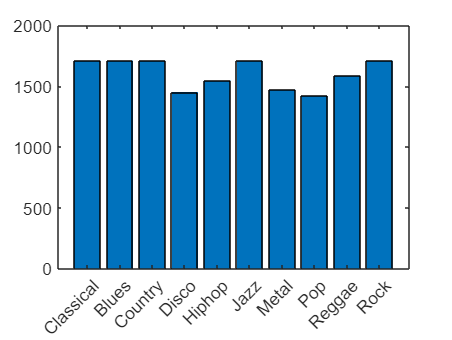



classical = 0;
blues = 0;
country = 0;
disco = 0;
hiphop = 0;
jazz = 0;
metal = 0;
pop = 0;
reggae = 0;
rock = 0;

if (0.5608<=mskewness)&&(mskewness<=2.4617)
    blues=blues + 58;
end
if (1.0381<=mskewness)&&(mskewness<=5.5545)
    classical = classical+58;
end
if (0.6620<=mskewness)&&(mskewness<=2.954)
    country = country + 58;
end
if (0.5477<=mskewness)&&(mskewness<=1.7287)
    disco = disco + 58;
end
if (0.4701<=mskewness)&&(mskewness<=1.8527)
    hiphop = hiphop +58;
end
if (0.3132<=mskewness)&&(mskewness<=4.2327)
    jazz = jazz + 58;
end
if (0.4642<=mskewness)&&(mskewness<=1.3501)
    metal = metal + 58;
end
if (0.2281<=mskewness)&&(mskewness<=1.9362)
    pop = pop + 58;
end
if (0.1500<=mskewness)&&(mskewness<=2.3235)
    reggae = reggae + 58;
end
if (0.6476<=mskewness)&&(mskewness<=2.0053)
    rock = rock + 58;
end


if (2336.6679<=rolloff)&&(rolloff<=6005.9342)
    blues=blues+57;
end
if (851.4657<=rolloff)&&(rolloff<=6994.5480)
    classical = classical+57;
end
if (1934.6447<=rolloff)&&(rolloff<=8208.8398)
    country = country + 57;
end
if (3513.4449<=rolloff)&&(rolloff<=8775.0326)
    disco = disco + 57;
end
if (3506.6947<=rolloff)&&(rolloff<=8402.3653)
    hiphop = hiphop +57;
end
if (1111.6305<=rolloff)&&(rolloff<=9038.4779)
    jazz = jazz + 57;
end
if (3838.1461<=rolloff)&&(rolloff<=8001.8351)
    metal = metal + 57;
end
if (4084.2640<=rolloff)&&(rolloff<=9351.6557)
    pop = pop + 57;
end
if (2906.688<=rolloff)&&(rolloff<=9065.5837)
    reggae = reggae + 57;
end
if (3337.4361<=rolloff)&&(rolloff<=8034.9129)
    rock = rock + 57;
end

if (1319.7233<=sspread)&&(sspread<=2628.7872)
    blues=blues+56;
end
if (958.5716<=sspread)&&(sspread<=3061.1397)
    classical = classical+56;
end
if (1308.1315<=sspread)&&(sspread<=3397.1141)
    country = country + 56;
end
if (1801.9683<=sspread)&&(sspread<=3506.0547)
    disco = disco + 56;
end
if (1775.9690<=sspread)&&(sspread<=3458.8851)
    hiphop = hiphop +56;
end
if (1167.2616<=sspread)&&(sspread<=3562.2439)
    jazz = jazz + 56;
end
if (1615.5793<=sspread)&&(sspread<=3281.5563)
    metal = metal + 56;
end
if (2327.0783<=sspread)&&(sspread<=3684.5928)
    pop = pop + 56;
end
if (1668.7252<=sspread)&&(sspread<=3498.0389)
    reggae = reggae + 56;
end
if (1615.9070<=sspread)&&(sspread<=3365.7996)
    rock = rock + 56;
end


if (0.8177<=mfcc1)&&(mfcc1<=3.8144)
    blues = blues +55;
end
if (1.1152<=mfcc1)&&(mfcc1<=5.5826) 
    classical = classical +55;
end
if (0.9451<=mfcc1)&&(mfcc1<=3.9917) 
    country = country +55;
end
if (0.8183<=mfcc1)&&(mfcc1<=2.8778) 
    disco = disco +55;
end
if (0.4589<=mfcc1)&&(mfcc1<=2.8620)
    hiphop = hiphop +55;
end
if (0.8111<=mfcc1)&&(mfcc1<=4.9821)
    jazz = jazz +55;
end
if (0.1807<=mfcc1)&&(mfcc1<=1.9929) 
    metal = metal + 55;
end
if(0.7019<=mfcc1)&&(mfcc1<=3.0346) 
    pop = pop + 55;
end
if (-0.0786<=mfcc1)&&(mfcc1<=3.1995) 
    reggae = reggae +55;
end
if (0.8385<=mfcc1)&&(mfcc1<=2.9703)
     rock = rock +55;
end

if (2.1139<=skurt)&&(skurt<=8.9268)
    blues=blues+54;
end
if (2.8966<=skurt)&&(skurt<=38.0158)
    classical = classical+54;
end
if (2.3404<=skurt)&&(skurt<=14.9872)
    country = country + 54;
end
if (1.8550<=skurt)&&(skurt<=5.8458)
    disco = disco + 54;
end
if (2.0512<=skurt)&&(skurt<=6.0892)
    hiphop = hiphop +54;
end
if (1.7980<=skurt)&&(skurt<=23.8149)
    jazz = jazz + 54;
end
if (2.1820<=skurt)&&(skurt<=4.2723)
    metal = metal + 54;
end
if (1.5655<=skurt)&&(skurt<=6.1432)
    pop = pop + 54;
end
if (1.7670<=skurt)&&(skurt<=9.4651)
    reggae = reggae + 54;
end
if (2.1276<=skurt)&&(skurt<=6.5974)
    rock = rock + 54;
end

if (0.0548<=rms_mean3)&&(rms_mean3<=0.2749)
    blues=blues+53;
end
if (0.0051<=rms_mean3)&&(rms_mean3<=0.1969)
    classical = classical+53;
end
if (0.0257<=rms_mean3)&&(rms_mean3<=0.2757)
    country = country + 53;
end
if (0.0522<=rms_mean3)&&(rms_mean3<=0.3083)
    disco = disco + 53;
end
if (0.0407<=rms_mean3)&&(rms_mean3<=0.3186)
    hiphop = hiphop +53;
end
if (0.0249<=rms_mean3)&&(rms_mean3<=0.2349)
    jazz = jazz + 53;
end
if (0.0412<=rms_mean3)&&(rms_mean3<=0.3151)
    metal = metal + 53;
end
if (0.0794<=rms_mean3)&&(rms_mean3<=0.3591)
    pop = pop + 53;
end
if (0.0311<=rms_mean3)&&(rms_mean3<=0.3603)
    reggae = reggae + 53;
end
if (0.0476<=rms_mean3)&&(rms_mean3<=0.2621)
    rock = rock + 53;
end

if (0.0419<=rms17)&&(rms17<=0.2880)
    blues=blues+52;
end
if (0.0037<=rms17)&&(rms17<=0.1750)
    classical = classical + 52;
end
if (0.0163<=rms17)&&(rms17<=0.2867)
    country = country + 52;
end
if (0.0550<=rms17)&&(rms17<=0.2874)
    disco = disco + 52;
end
if (0.0581<=rms17)&&(rms17<=0.3499)
    hiphop = hiphop +52;
end
if (0.0198<=rms17)&&(rms17<=0.2390)
    jazz = jazz + 52;
end
if (0.0458<=rms17)&&(rms17<=0.3209)
    metal = metal + 52;
end
if (0.0828<=rms17)&&(rms17<=0.3687)
    pop = pop + 52;
end
if (0.0162<=rms17)&&(rms17<=0.4182)
    reggae = reggae + 52;
end
if (0.0265<=rms17)&&(rms17<=0.2393)
    rock = rock + 52;
end

if (1120.8496<=mcentroid)&&(mcentroid<=2849.0647)
    blues=blues+51;
end
if (715.9706<=mcentroid)&&(mcentroid<=3051.0105)
    classical = classical+51;
end
if (1058.7377<=mcentroid)&&(mcentroid<=3158.4785)
    country = country + 51;
end
if (1851.0207<=mcentroid)&&(mcentroid<=3634.5209)
    disco = disco + 51;
end
if (1710.6475<=mcentroid)&&(mcentroid<=3365.8647)
    hiphop = hiphop +51;
end
if (744.8207<=mcentroid)&&(mcentroid<=4076.9035)
    jazz = jazz + 51;
end
if (1756.5867<=mcentroid)&&(mcentroid<=2951.3535)
    metal = metal + 51;
end
if (1950.6719<=mcentroid)&&(mcentroid<=3843.8604)
    pop = pop + 51;
end
if (1497.1648<=mcentroid)&&(mcentroid<=5000.0773)
    reggae = reggae + 51;
end
if (1718.4113<=mcentroid)&&(mcentroid<=3422.6298)
    rock = rock + 51;
end

if (0.0324<=rms8)&&(rms8<=0.2805)
    blues=blues+50;
end
if (0.0012<=rms8)&&(rms8<=0.1938)
    classical = classical + 50;
end
if (0.0284<=rms8)&&(rms8<=0.2808)
    country = country + 50;
end
if (0.0380<=rms8)&&(rms8<=0.2913)
    disco = disco + 50;
end
if (0.0266<=rms8)&&(rms8<=0.3428)
    hiphop = hiphop +50;
end
if (0.0257<=rms8)&&(rms8<=0.2470)
    jazz = jazz + 50;
end
if (0.0351<=rms8)&&(rms8<=0.3357)
    metal = metal + 50;
end
if (0.0642<=rms8)&&(rms8<=0.3604)
    pop = pop + 50;
end
if (0.0409<=rms8)&&(rms8<=0.4152)
    reggae = reggae + 50;
end
if (0.0448<=rms8)&&(rms8<=0.2819)
    rock = rock + 50;
end

if (0.0341<=rms7)&&(rms7<=0.2807)
    blues=blues+49;
end
if (0.0017<=rms7)&&(rms7<=0.2024)
    classical = classical + 49;
end
if (0.0246<=rms7)&&(rms7<=0.2728)
    country = country + 49;
end
if (0.0358<=rms7)&&(rms7<=0.2988)
    disco = disco + 49;
end
if (0.0251<=rms7)&&(rms7<=0.3437)
    hiphop = hiphop +49;
end
if (0.0161<=rms7)&&(rms7<=0.2346)
    jazz = jazz + 49;
end
if (0.0351<=rms7)&&(rms7<=0.3316)
    metal = metal + 49;
end
if (0.0732<=rms7)&&(rms7<=0.3555)
    pop = pop + 49;
end
if (0.0445<=rms7)&&(rms7<=0.4144)
    reggae = reggae + 49;
end
if (0.0202<=rms7)&&(rms7<=0.2767)
    rock = rock + 49;
end

if (0.0599<=rms18)&&(rms18<=0.2809)
    blues=blues+48;
end
if (0.0047<=rms18)&&(rms18<=0.1783)
    classical = classical + 48;
end
if (0.0150<=rms18)&&(rms18<=0.2852)
    country = country + 48;
end
if (0.0585<=rms18)&&(rms18<=0.3396)
    disco = disco + 48;
end
if (0.0769<=rms18)&&(rms18<=0.3530)
    hiphop = hiphop +48;
end
if (0.0167<=rms18)&&(rms18<=0.2358)
    jazz = jazz + 48;
end
if (0.0503<=rms18)&&(rms18<=0.3200)
    metal = metal + 48;
end
if (0.0818<=rms18)&&(rms18<=0.3682)
    pop = pop + 48;
end
if (0.0231<=rms18)&&(rms18<=0.4174)
    reggae = reggae + 48;
end
if (0.0402<=rms18)&&(rms18<=0.2637)
    rock = rock + 48;
end

if (0.0258<=rms11)&&(rms11<=0.3110)
    blues=blues+47;
end
if (0.0010<=rms11)&&(rms11<=0.2368)
    classical = classical + 47;
end
if (0.0266<=rms11)&&(rms11<=0.2830)
    country = country + 47;
end
if (0.0572<=rms11)&&(rms11<=0.3167)
    disco = disco + 47;
end
if (0.0549<=rms11)&&(rms11<=0.3524)
    hiphop = hiphop +47;
end
if (0.0170<=rms11)&&(rms11<=0.2516)
    jazz = jazz + 47;
end
if (0.0419<=rms11)&&(rms11<=0.3165)
    metal = metal + 47;
end
if (0.0793<=rms11)&&(rms11<=0.3473)
    pop = pop + 47;
end
if (0.0277<=rms11)&&(rms11<=0.4180)
    reggae = reggae + 47;
end
if (0.0301<=rms11)&&(rms11<=0.2535)
    rock = rock + 47;
end

if (0.0412<=rms16)&&(rms16<=0.3197)
    blues=blues + 46;
end
if (0.0045<=rms16)&&(rms16<=0.1616)
    classical = classical + 46;
end
if (0.0144<=rms16)&&(rms16<=0.2741)
    country = country + 46;
end
if (0.0572<=rms16)&&(rms16<=0.3042)
    disco = disco + 46;
end
if (0.0399<=rms16)&&(rms16<=0.3503)
    hiphop = hiphop + 46;
end
if (0.0128<=rms16)&&(rms16<=0.2317)
    jazz = jazz + 46;
end
if (0.0446<=rms16)&&(rms16<=0.3213)
    metal = metal + 46;
end
if (0.0815<=rms16)&&(rms16<=0.3972)
    pop = pop + 46;
end
if (0.0264<=rms16)&&(rms16<=0.4176)
    reggae = reggae + 46;
end
if (0.0158<=rms16)&&(rms16<=0.2361)
    rock = rock + 46;
end

if (0.0541<=rms19)&&(rms19<=0.2802)
    blues=blues + 45;
end
if (0.0052<=rms19)&&(rms19<=0.1724)
    classical = classical + 45;
end
if (0.0335<=rms19)&&(rms19<=0.2853)
    country = country + 45;
end
if (0.0576<=rms19)&&(rms19<=0.3896)
    disco = disco + 45;
end
if (0.0825<=rms19)&&(rms19<=0.3467)
    hiphop = hiphop + 45;
end
if (0.0166<=rms19)&&(rms19<=0.2330)
    jazz = jazz + 45;
end
if (0.0500<=rms19)&&(rms19<=0.3243)
    metal = metal + 45;
end
if (0.0870<=rms19)&&(rms19<=0.3697)
    pop = pop + 45;
end
if (0.0259<=rms19)&&(rms19<=0.4154)
    reggae = reggae + 45;
end
if (0.0424<=rms19)&&(rms19<=0.2705)
    rock = rock + 45;
end

if (0.0265<=rms6)&&(rms6<=0.2943)
    blues=blues + 44;
end
if (0.0022<=rms6)&&(rms6<=0.2145)
    classical = classical + 44;
end
if (0.0284<=rms6)&&(rms6<=0.2760)
    country = country + 44;
end
if (0.0233<=rms6)&&(rms6<=0.3073)
    disco = disco + 44;
end
if (0.0217<=rms6)&&(rms6<=0.3394)
    hiphop = hiphop + 44;
end
if (0.0223<=rms6)&&(rms6<=0.2405)
    jazz = jazz + 44;
end
if (0.0372<=rms6)&&(rms6<=0.3306)
    metal = metal + 44;
end
if (0.0533<=rms6)&&(rms6<=0.3641)
    pop = pop + 44;
end
if (0.0351<=rms6)&&(rms6<=0.4147)
    reggae = reggae + 44;
end
if (0.0154<=rms6)&&(rms6<=0.2754)
    rock = rock + 44;
end

if (0.0431<=rms15)&&(rms15<=0.2915)
    blues=blues+43;
end
if (0.0036<=rms15)&&(rms15<=0.1854)
    classical = classical + 43;
end
if (0.0124<=rms15)&&(rms15<=0.2569)
    country = country + 43;
end
if (0.0591<=rms15)&&(rms15<=0.3117)
    disco = disco + 43;
end
if (0.0338<=rms15)&&(rms15<=0.3536)
    hiphop = hiphop +43;
end
if (0.0174<=rms15)&&(rms15<=0.2285)
    jazz = jazz + 43;
end
if (0.0483<=rms15)&&(rms15<=0.3209)
    metal = metal + 43;
end
if (0.0753<=rms15)&&(rms15<=0.3637)
    pop = pop + 43;
end
if (0.0317<=rms15)&&(rms15<=0.4158)
    reggae = reggae + 43;
end
if (0.0377<=rms15)&&(rms15<=0.2431)
    rock = rock + 43;
end

if (0.0473<=rms14)&&(rms14<=0.2968)
    blues=blues+42;
end
if (0.0029<=rms14)&&(rms14<=0.2138)
    classical = classical + 42;
end
if (0.0115<=rms14)&&(rms14<=0.2652)
    country = country + 42;
end
if (0.0610<=rms14)&&(rms14<=0.2964)
    disco = disco + 42;
end
if (0.0333<=rms14)&&(rms14<=0.3530)
    hiphop = hiphop +42;
end
if (0.0134<=rms14)&&(rms14<=0.2330)
    jazz = jazz + 42;
end
if (0.0451<=rms14)&&(rms14<=0.3195)
    metal = metal + 42;
end
if (0.0739<=rms14)&&(rms14<=0.3823)
    pop = pop + 42;
end
if (0.0272<=rms14)&&(rms14<=0.4144)
    reggae = reggae + 42;
end
if (0.0289<=rms14)&&(rms14<=0.2732)
    rock = rock + 42;
end

if (0.0614<=rms12)&&(rms12<=0.2953)
    blues=blues + 41;
end
if (0.0013<=rms12)&&(rms12<=0.2286)
    classical = classical + 41;
end
if (0.0211<=rms12)&&(rms12<=0.2722)
    country = country + 41;
end
if (0.0297<=rms12)&&(rms12<=0.2925)
    disco = disco + 41;
end
if (0.0483<=rms12)&&(rms12<=0.3384)
    hiphop = hiphop + 41;
end
if (0.0116<=rms12)&&(rms12<=0.2235)
    jazz = jazz + 41;
end
if (0.0467<=rms12)&&(rms12<=0.3216)
    metal = metal + 41;
end
if (0.0789<=rms12)&&(rms12<=0.3572)
    pop = pop + 41;
end
if (0.0228<=rms12)&&(rms12<=0.4161)
    reggae = reggae + 41;
end
if (0.0251<=rms12)&&(rms12<=0.2821)
    rock = rock + 41;
end

if (0.0544<=rms10)&&(rms10<=0.2976)
    blues=blues + 40;
end
if (0.0010<=rms10)&&(rms10<=0.2328)
    classical = classical + 40;
end
if (0.0307<=rms10)&&(rms10<=0.2958)
    country = country + 40;
end
if (0.0567<=rms10)&&(rms10<=0.3116)
    disco = disco + 40;
end
if (0.0426<=rms10)&&(rms10<=0.3458)
    hiphop = hiphop +40;
end
if (0.0213<=rms10)&&(rms10<=0.2899)
    jazz = jazz + 40;
end
if (0.0372<=rms10)&&(rms10<=0.3129)
    metal = metal + 40;
end
if (0.0775<=rms10)&&(rms10<=0.3368)
    pop = pop + 40;
end
if (0.0432<=rms10)&&(rms10<=0.4181)
    reggae = reggae + 40;
end
if (0.0437<=rms10)&&(rms10<=0.2691)
    rock = rock + 40;
end

if (0.0622<=rms13)&&(rms13<=0.3123)
    blues=blues+ 39;
end
if (0.0018<=rms13)&&(rms13<=0.2018)
    classical = classical + 39;
end
if (0.0136<=rms13)&&(rms13<=0.2734)
    country = country + 39;
end
if (0.0557<=rms13)&&(rms13<=0.2865)
    disco = disco + 39;
end
if (0.0399<=rms13)&&(rms13<=0.3456)
    hiphop = hiphop + 39;
end
if (0.0104<=rms13)&&(rms13<=0.2425)
    jazz = jazz + 39;
end
if (0.0477<=rms13)&&(rms13<=0.3179)
    metal = metal + 39;
end
if (0.0767<=rms13)&&(rms13<=0.3657)
    pop = pop + 39;
end
if (0.0253<=rms13)&&(rms13<=0.4144)
    reggae = reggae + 39;
end
if (0.0240<=rms13)&&(rms13<=0.2786)
    rock = rock + 39;
end

if (0.0427<=rms9)&&(rms9<=0.3003)
    blues=blues+38;
end
if (0.0009<=rms9)&&(rms9<=0.2165)
    classical = classical + 38;
end
if (0.0299<=rms9)&&(rms9<=0.2940)
    country = country + 38;
end
if (0.0322<=rms9)&&(rms9<=0.2833)
    disco = disco + 38;
end
if (0.0196<=rms9)&&(rms9<=0.3369)
    hiphop = hiphop + 38;
end
if (0.0249<=rms9)&&(rms9<=0.2960)
    jazz = jazz + 38;
end
if (0.0349<=rms9)&&(rms9<=0.3309)
    metal = metal + 38;
end
if (0.0745<=rms9)&&(rms9<=0.3627)
    pop = pop + 38;
end
if (0.0424<=rms9)&&(rms9<=0.4170)
    reggae = reggae + 38;
end
if (0.0440<=rms9)&&(rms9<=0.2767)
    rock = rock + 38;
end

if (0.0446<=rms5)&&(rms5<=0.2846)
    blues=blues + 37;
end
if (0.0039<=rms5)&&(rms5<=0.2055)
    classical = classical + 37;
end
if (0.0294<=rms5)&&(rms5<=0.2695)
    country = country + 37;
end
if (0.0256<=rms5)&&(rms5<=0.3037)
    disco = disco + 37;
end
if (0.0239<=rms5)&&(rms5<=0.3376)
    hiphop = hiphop +37;
end
if (0.0245<=rms5)&&(rms5<=0.2383)
    jazz = jazz + 37;
end
if (0.0372<=rms5)&&(rms5<=0.3142)
    metal = metal + 37;
end
if (0.0549<=rms5)&&(rms5<=0.3569)
    pop = pop + 37;
end
if (0.0348<=rms5)&&(rms5<=0.3336)
    reggae = reggae + 37;
end
if (0.0245<=rms5)&&(rms5<=0.2749)
    rock = rock + 37;
end

if (0.0320<=rms4)&&(rms4<=0.2849)
    blues=blues + 36;
end
if (0.0047<=rms4)&&(rms4<=0.2159)
    classical = classical + 36;
end
if (0.0238<=rms4)&&(rms4<=0.2623)
    country = country + 36;
end
if (0.0362<=rms4)&&(rms4<=0.3001)
    disco = disco + 36;
end
if (0.0335<=rms4)&&(rms4<=0.3086)
    hiphop = hiphop + 36;
end
if (0.0182<=rms4)&&(rms4<=0.2399)
    jazz = jazz + 36;
end
if (0.0356<=rms4)&&(rms4<=0.3204)
    metal = metal + 36;
end
if (0.0365<=rms4)&&(rms4<=0.3564)
    pop = pop + 36;
end
if (0.0306<=rms4)&&(rms4<=0.3123)
    reggae = reggae + 36;
end
if (0.0245<=rms4)&&(rms4<=0.2682)
    rock = rock + 36;
end


if (0.0221<=rms3)&&(rms3<=0.2822)
    blues=blues + 35;
end
if (0.0036<=rms3)&&(rms3<=0.2258)
    classical = classical + 35;
end
if (0.0287<=rms3)&&(rms3<=0.2623)
    country = country + 35;
end
if (0.0495<=rms3)&&(rms3<=0.2986)
    disco = disco + 35;
end
if (0.0329<=rms3)&&(rms3<=0.3393)
    hiphop = hiphop +35;
end
if (0.0231<=rms3)&&(rms3<=0.2435)
    jazz = jazz + 35;
end
if (0.0358<=rms3)&&(rms3<=0.3172)
    metal = metal + 35;
end
if (0.0335<=rms3)&&(rms3<=0.3608)
    pop = pop + 35;
end
if (0.0333<=rms3)&&(rms3<=0.2968)
    reggae = reggae + 35;
end
if (0.0236<=rms3)&&(rms3<=0.2654)
    rock = rock + 35;
end

 if (0.0246<=rms2)&&(rms2<=0.2834)
    blues=blues+34;
end
if (0.0025<=rms2)&&(rms2<=0.2067)
    classical = classical + 34;
end
if (0.0289<=rms2)&&(rms2<=0.2662)
    country = country + 34;
end
if (0.0439<=rms2)&&(rms2<=0.2898)
    disco = disco + 34;
end
if (0.0187<=rms2)&&(rms2<=0.3258)
    hiphop = hiphop + 34;
end
if (0.0162<=rms2)&&(rms2<=0.2491)
    jazz = jazz + 34;
end
if (0.0355<=rms2)&&(rms2<=0.2976)
    metal = metal + 34;
end
if (0.0386<=rms2)&&(rms2<=0.3694)
    pop = pop + 34;
end
if (0.0241<=rms2)&&(rms2<=0.3220)
    reggae = reggae + 34;
end
if (0.0279<=rms2)&&(rms2<=0.2722)
    rock = rock + 34;
end


 if (0.03713<=rms1)&&(rms1<=0.2898)
    blues=blues+ 33;
end
if (0.0039<=rms1)&&(rms1<=0.2107)
    classical = classical + 33;
end
if (0.0207<=rms1)&&(rms1<=0.2765)
    country = country + 33;
end
if (0.0332<=rms1)&&(rms1<=0.3492)
    disco = disco + 33;
end
if (0.0230<=rms1)&&(rms1<=0.3422)
    hiphop = hiphop +33;
end
if (0.0211<=rms1)&&(rms1<=0.2480)
    jazz = jazz + 33;
end
if (0.0368<=rms1)&&(rms1<=0.3040)
    metal = metal + 32;
end
if (0.0424<=rms1)&&(rms1<=0.3687)
    pop = pop + 33;
end
if (0.0197<=rms1)&&(rms1<=0.3359)
    reggae = reggae + 33;
end
if (0.0254<=rms1)&&(rms1<=0.2676)
    rock = rock + 33;
end


if (0.2106<=b)&&(b<=0.6179)
    blues=blues+32;
end
if (0.0684<=b)&&(b<=0.7460)
    classical = classical+32;
end
if (0.2056<=b)&&(b<=0.6801)
    country = country + 32;
end
if (0.3571<=b)&&(b<=0.6858)
    disco = disco + 32;
end
if (0.3101<=b)&&(b<=0.6958)
    hiphop = hiphop +32;
end
if (0.0805<=b)&&(b<=0.7388)
    jazz = jazz + 32;
end
if (0.4045<=b)&&(b<=0.7207)
    metal = metal + 32;
end
if (0.3701<=b)&&(b<=0.6971)
    pop = pop + 32;
end
if (0.3139<=b)&&(b<=0.8032)
    reggae = reggae + 32;
end
if (0.3140<=b)&&(b<=0.6719)
    rock = rock + 32;
end


if (0.1361<=cent2)&&(cent2<=0.9819)
    blues=blues+31;
end
if (0.0697<=cent2)&&(cent2<=1)
    classical = classical+31;
end
if (0.1363<=cent2)&&(cent2<=1)
    country = country + 31;
end
if (0.3467<=cent2)&&(cent2<=1)
    disco = disco + 31;
end
if (0.2278<=cent2)&&(cent2<=1)
    hiphop = hiphop +31;
end
if (0.1146<=cent2)&&(cent2<=1)
    jazz = jazz + 31;
end
if (0.1973<=cent2)&&(cent2<=1)
    metal = metal + 31;
end
if (0.3239<=cent2)&&(cent2<=1)
    pop = pop + 31;
end
if (0.2366<=cent2)&&(cent2<=1)
    reggae = reggae + 31;
end
if (0.2766<=cent2)&&(cent2<=1)
    rock = rock + 31;
end

if (-1.0445<=mfcc2)&&(mfcc2<=1.1299)
    blues = blues +30;
end
if (-1.1556<=mfcc2)&&(mfcc2<=0.5479)
    classical = classical +30;
end
if (-0.9609<=mfcc2)&&(mfcc2<=1.0754)
    country = country +30;
end
if (-1.0980<=mfcc2)&&(mfcc2<=0.7736)
    disco = disco +30;
end
if (-0.7920<=mfcc2)&&(mfcc2<=0.8936) 
    hiphop = hiphop +30;
end
if (-1.2965<=mfcc2)&&(mfcc2<=1.1861)
    jazz = jazz +30;
end
if (-0.9431<=mfcc2)&&(mfcc2<=0.9223)
    metal = metal + 30;
end
if(-0.8562<=mfcc2)&&(mfcc2<=0.7912)
    pop = pop +30;
end
if (-1.0503<=mfcc2)&&(mfcc2<=0.8508)
    reggae = reggae +30;
end
if (-1.0547<=mfcc2)&&(mfcc2<=0.7918)
    rock = rock +30;
end




if (0.2697<=cent12)&&(cent12<=1)
    blues=blues+29;
end
if (0.1028<=cent12)&&(cent12<=1)
    classical = classical+29;
end
if (0.1597<=cent12)&&(cent12<=1)
    country = country + 29;
end
if (0.3531<=cent12)&&(cent12<=1)
    disco = disco + 29;
end
if (0.2618<=cent12)&&(cent12<=1)
    hiphop = hiphop +29;
end
if (0.1189<=cent12)&&(cent12<=1)
    jazz = jazz + 29;
end
if (0.3132<=cent12)&&(cent12<=1)
    metal = metal + 29;
end
if (0.2524<=cent12)&&(cent12<=1)
    pop = pop + 29;
end
if (0.2831<=cent12)&&(cent12<=1)
    reggae = reggae + 29;
end
if (0.3106<=cent12)&&(cent12<=1)
    rock = rock + 29;
end


if (0.0755<=sflat)&&(sflat<=0.4281)
    blues=blues+28;
end
if (0.0540<=sflat)&&(sflat<=0.5629)
    classical = classical+28;
end
if (0.0884<=sflat)&&(sflat<=0.6787)
    country = country + 28;
end
if (0.1682<=sflat)&&(sflat<=0.7026)
    disco = disco + 28;
end
if (0.1643<=sflat)&&(sflat<=0.6449)
    hiphop = hiphop +28;
end
if (0.0560<=sflat)&&(sflat<=0.6870)
    jazz = jazz + 28;
end
if (0.1388<=sflat)&&(sflat<=0.6684)
    metal = metal + 28;
end
if (0.3732<=sflat)&&(sflat<=0.7431)
    pop = pop + 28;
end
if (0.1588<=sflat)&&(sflat<=0.7546)
    reggae = reggae + 28;
end
if (0.1402<=sflat)&&(sflat<=0.6686)
    rock = rock + 28;
end




if (0.2289<=mkey_clarity)&&(mkey_clarity<=0.8933)
    blues=blues+27;
end
if (0.3749<=mkey_clarity)&&(mkey_clarity<=0.9614)
    classical = classical+27;
end
if (0.5145<=mkey_clarity)&&(mkey_clarity<=0.9475)
    country = country + 27;
end
if (0.3690<=mkey_clarity)&&(mkey_clarity<=0.9506)
    disco = disco + 27;
end
if (0.1405<=mkey_clarity)&&(mkey_clarity<=0.7748)
    hiphop = hiphop +27;
end
if (0.2527<=mkey_clarity)&&(mkey_clarity<=0.8804)
    jazz = jazz + 27;
end
if (0.2991<=mkey_clarity)&&(mkey_clarity<=0.8390)
    metal = metal + 27;
end
if (0.1893<=mkey_clarity)&&(mkey_clarity<=0.9290)
    pop = pop + 27;
end
if (0.2974<=mkey_clarity)&&(mkey_clarity<=0.9318)
    reggae = reggae + 27;
end
if (0.2199<=mkey_clarity)&&(mkey_clarity<=0.9419)
    rock = rock + 27;
end

if (0.2455<=cent11)&&(cent11<=1)
    blues=blues+26;
end
if (0.0916<=cent11)&&(cent11<=1)
    classical = classical + 26;
end
if (0.1683<=cent11)&&(cent11<=1)
    country = country + 26;
end
if (0.2958<=cent11)&&(cent11<=1)
    disco = disco + 26;
end
if (0.3063<=cent11)&&(cent11<=1)
    hiphop = hiphop +26;
end
if (0.1511<=cent11)&&(cent11<=1)
    jazz = jazz + 26;
end
if (0.2805<=cent11)&&(cent11<=1)
    metal = metal + 26;
end
if (0.3396<=cent11)&&(cent11<=1)
    pop = pop + 26;
end
if (0.2694<=cent11)&&(cent11<=1)
    reggae = reggae + 26;
end
if (0.2713<=cent11)&&(cent11<=1)
    rock = rock + 26;
end


if (236.7447<=z)&&(z<=1848.3786)
    blues=blues+25;
end
if (296.0684<=z)&&(z<=1678.3708)
    classical=classical+25;
end
if (390.0099<=z)&&(z<=2342.9754)
    country=country + 25;
end
if (593.6528<=z)&&(z<=2190.2599)
    disco=disco+25;
end
if (467.9920<=z)&&(z<=2358.6826)
    hiphop=hiphop+25;
end
if (348.3784<=z)&&(z<=2885.4343)
    jazz=jazz+25;
end
if (513.2802<=z)&&(z<=2246.0531)
    metal=metal+25;
end
if (569.3465<=z)&&(z<=2540.8847)
    pop=pop+25;
end
if (284.4402<=z)&&(z<=3028.7817)
    reggae=reggae+25;
end
if (453.1985<=z)&&(z<=2069.9134)
    rock=rock+25;
end


if (0.1378<=cent4)&&(cent4<=1)
    blues=blues+24;
end
if (0.0631<=cent4)&&(cent4<=1)
    classical = classical+24;
end
if (0.1284<=cent4)&&(cent4<=1)
    country = country + 24;
end
if (0.2955<=cent4)&&(cent4<=0.8912)
    disco = disco + 24;
end
if (0.1977<=cent4)&&(cent4<=1)
    hiphop = hiphop +24;
end
if (0.1175<=cent4)&&(cent4<=0.9936)
    jazz = jazz + 24;
end
if (0.3260<=cent4)&&(cent4<=1)
    metal = metal + 24;
end
if (0.2281<=cent4)&&(cent4<=1)
    pop = pop + 24;
end
if (0.1837<=cent4)&&(cent4<=0.8730)
    reggae = reggae + 24;
end
if (0.2125<=cent4)&&(cent4<=1)
    rock = rock + 24;
end

if (-0.5891<=mfcc10)&&(mfcc10<=0.3453)
    blues = blues + 23;
end
if (-0.3577<=mfcc10)&&(mfcc10<=0.3523)
    classical = classical +23;
end
if (-0.2674<=mfcc10)&&(mfcc10<=0.4762)
    country = country +23;
end
if (-0.0926<=mfcc10)&&(mfcc10<=0.2748)
    disco = disco +23;
end
if (-0.1315<=mfcc10)&&(mfcc10<=0.3551)
    hiphop = hiphop +23;
end
if (-0.4377<=mfcc10)&&(mfcc10<=0.3420)
    jazz = jazz + 23;
end
if (-0.1720<=mfcc10)&&(mfcc10<=0.3354)
    metal = metal + 23;
end
if (-0.2235<=mfcc10)&&(mfcc10<=0.2982)
    pop = pop +23;
end
if (-0.3433<=mfcc10)&&(mfcc10<=0.3357)
    reggae = reggae +23;
end
if (-0.3362<=mfcc10)&&(mfcc10<=0.3685)
    rock = rock +23;
end

if (-0.3136<=mfcc11)&&(mfcc11<=0.5358)
    blues = blues +22;
end
if (-0.3436<=mfcc11)&&(mfcc11<=0.3279) 
    classical = classical +22;
end
if (-0.3581<=mfcc11)&&(mfcc11<=0.2431)
    country = country + 22;
end
if (-0.3182<=mfcc11)&&(mfcc11<=0.3273)
    disco = disco +22;
end
if (-0.2108<=mfcc11)&&(mfcc11<=0.2694)
    hiphop = hiphop +22;
end
if (-0.3084<=mfcc11)&&(mfcc11<=0.4251)
    jazz = jazz +22;
end
if (-0.2337<=mfcc11)&&(mfcc11<=0.3762)
    metal = metal + 22;
end
if(-0.1827<=mfcc11)&&(mfcc11<=0.2523)
    pop = pop +22;
end
if (-0.2648<=mfcc11)&&(mfcc11<=0.3988)
    reggae = reggae +22;
end
if (-0.1879<=mfcc11)&&(mfcc11<=0.1612)
    rock = rock +22;
end

if (0.0031<=rms_std)&&(rms_std<=0.0648)
    blues=blues + 21;
end
if (0.0014<=rms_std)&&(rms_std<=0.0524)
    classical = classical + 21;
end
if (0.0039<=rms_std)&&(rms_std<=0.0415)
    country = country + 21;
end
if (0.0024<=rms_std)&&(rms_std<=0.0261)
    disco = disco + 21;
end
if (0.0026<=rms_std)&&(rms_std<=0.0854)
    hiphop = hiphop + 21;
end
if (0.0033<=rms_std)&&(rms_std<=0.0453)
    jazz = jazz + 21;
end
if (0.0025<=rms_std)&&(rms_std<=0.0678)
    metal = metal + 21;
end
if (0.0029<=rms_std)&&(rms_std<=0.0728)
    pop = pop + 21;
end
if (0.0018<=rms_std)&&(rms_std<=0.1018)
    reggae = reggae + 21;
end
if (0.0051<=rms_std)&&(rms_std<=0.0544)
    rock = rock + 21;
end

if (77.6876<=pitch1)&&(pitch1<=1649.8617)
    blues=blues+20;
end
if (77.9550<=pitch1)&&(pitch1<=1102.4834)
    classical = classical+20;
end
if (82.5796<=pitch1)&&(pitch1<=1178.2100)
    country = country + 20;
end
if (78.3790<=pitch1)&&(pitch1<=1295.0524)
    disco = disco + 20;
end
if (78.1748<=pitch1)&&(pitch1<=1283.9548)
    hiphop = hiphop +20;
end
if (77.8609<=pitch1)&&(pitch1<=1173.0164)
    jazz = jazz + 20;
end
if (80.6656<=pitch1)&&(pitch1<=1205.0392)
    metal = metal + 20;
end
if (77.7664<=pitch1)&&(pitch1<=1176.0915)
    pop = pop + 20;
end
if (76.2936<=pitch1)&&(pitch1<=1285.4779)
    reggae = reggae + 20;
end
if (76.5788<=pitch1)&&(pitch1<=1315.8414)
    rock = rock + 20;
end

if (0.1653<=cent7)&&(cent7<=0.7778)
    blues=blues + 19;
end
if (0.0573<=cent7)&&(cent7<=1)
    classical = classical + 19;
end
if (0.1682<=cent7)&&(cent7<=1)
    country = country + 19;
end
if (0.2260<=cent7)&&(cent7<=1)
    disco = disco + 19;
end
if (0.1938<=cent7)&&(cent7<=0.8650)
    hiphop = hiphop + 19;
end
if (0.1118<=cent7)&&(cent7<=0.9230)
    jazz = jazz + 19;
end
if (0.1622<=cent7)&&(cent7<=1)
    metal = metal + 19;
end
if (0.2661<=cent7)&&(cent7<=0.9892)
    pop = pop + 19;
end
if (0.2038<=cent7)&&(cent7<=1)
    reggae = reggae + 19;
end
if (0.2676<=cent7)&&(cent7<=1)
    rock = rock + 19;
end

if (-0.4292<=mfcc9)&&(mfcc9<=0.4935)
    blues = blues +18;
end
if (-0.4425<=mfcc9)&&(mfcc9<=0.3325)
    classical = classical + 18;
end
if (-0.3212<=mfcc9)&&(mfcc9<=0.3424)
    country = country +18;
end
if (-0.3785<=mfcc9)&&(mfcc9<=0.3195)
    disco = disco +18;
end
if (-0.1897<=mfcc9)&&(mfcc9<=0.3747)
    hiphop = hiphop +18;
end
if (-0.7154<=mfcc9)&&(mfcc9<=0.4350)
    jazz = jazz +18;
end
if (-0.1849<=mfcc9)&&(mfcc9<=0.4429)
    metal = metal + 18;
end
if(-0.2345<=mfcc9)&&(mfcc9<=0.2425)
    pop = pop +18;
end
if (-0.3629<=mfcc9)&&(mfcc9<=0.4764)
    reggae = reggae +18;
end
if (-0.1693<=mfcc9)&&(mfcc9<=0.2774)
    rock = rock +18;
end

if (0.1790<=cent1)&&(cent1<=1)
    blues=blues + 17;
end
if (0.0897<=cent1)&&(cent1<=1)
    classical = classical + 17;
end
if (0.1156<=cent1)&&(cent1<=1)
    country = country + 17;
end
if (0.2684<=cent1)&&(cent1<=1)
    disco = disco + 17;
end
if (0.2175<=cent1)&&(cent1<=1)
    hiphop = hiphop + 17;
end
if (0.1963<=cent1)&&(cent1<=1)
    jazz = jazz + 17;
end
if (0.2216<=cent1)&&(cent1<=1)
    metal = metal + 17;
end
if (0.3283<=cent1)&&(cent1<=1)
    pop = pop + 17;
end
if (0.2961<=cent1)&&(cent1<=1)
    reggae = reggae + 17;
end
if (0.2214<=cent1)&&(cent1<=1)
    rock = rock + 17;
end

if (0.2075<=cent9)&&(cent9<=1)
    blues=blues + 16;
end
if (0.0786<=cent9)&&(cent9<=1)
    classical = classical + 16;
end
if (0.2550<=cent9)&&(cent9<=1)
    country = country + 16;
end
if (0.2526<=cent9)&&(cent9<=1)
    disco = disco + 16;
end
if (0.4724<=cent9)&&(cent9<=1)
    hiphop = hiphop + 16;
end
if (0.1514<=cent9)&&(cent9<=1)
    jazz = jazz + 16;
end
if (0.4088<=cent9)&&(cent9<=1)
    metal = metal + 16;
end
if (0.3861<=cent9)&&(cent9<=1)
    pop = pop + 16;
end
if (0.2970<=cent9)&&(cent9<=1)
    reggae = reggae + 16;
end
if (0.2634<=cent9)&&(cent9<=1)
    rock = rock + 16;
end

 if (-0.6167<=mfcc4)&&(mfcc4<=0.8596)
    blues = blues + 15;
end
if (-0.5652<=mfcc4)&&(mfcc4<=0.4350)
    classical = classical +15;
end
if (-0.6083<=mfcc4)&&(mfcc4<=0.3996)
    country = country +15;
end
if (-0.3115<=mfcc4)&&(mfcc4<=0.3949) 
    disco = disco +15;
end
if (-0.4107<=mfcc4)&&(mfcc4<=0.3609) 
    hiphop = hiphop +15;
end
if (-0.8942<=mfcc4)&&(mfcc4<=0.5805) 
    jazz = jazz +15;
end
if (-0.4324<=mfcc4)&&(mfcc4<=0.4114) 
    metal = metal + 15;
end
if(-0.6137<=mfcc4)&&(mfcc4<=0.5129) 
    pop = pop +15;
end
if (-0.6756<=mfcc4)&&(mfcc4<=0.5815) 
    reggae = reggae +15;
end
if (-0.4728<=mfcc4)&&(mfcc4<=0.6502)
    rock = rock +15;
end

 if (-0.4014<=mfcc12)&&(mfcc12<=0.4728)
    blues = blues +14;
end
if (-0.3758<=mfcc12)&&(mfcc12<=0.2809)
    classical = classical +14;
end
if (-0.3435<=mfcc12)&&(mfcc12<=0.3289)
    country = country +14;
end
if (-0.2955<=mfcc12)&&(mfcc12<=0.2547)
    disco = disco +14;
end
if (-0.2022<=mfcc12)&&(mfcc12<=0.3278) 
    hiphop = hiphop +14;
end
if (-0.5742<=mfcc12)&&(mfcc12<=0.2813)
    jazz = jazz +14;
end
if (-0.1642<=mfcc12)&&(mfcc12<=0.3362)
    metal = metal + 14;
end
if(-0.2578<=mfcc12)&&(mfcc12<=0.1936)
    pop = pop +13;
end
if (-0.2857<=mfcc12)&&(mfcc12<=0.3595)
    reggae = reggae +14;
end
if (-0.1789<=mfcc12)&&(mfcc12<=0.2883)
    rock = rock +14;
end

if (0.2107<=cent10)&&(cent10<=1)
    blues=blues + 13;
end
if (0.0980<=cent10)&&(cent10<=1)
    classical = classical + 13;
end
if (0.3011<=cent10)&&(cent10<=1)
    country = country + 13;
end
if (0.2154<=cent10)&&(cent10<=1)
    disco = disco + 13;
end
if (0.4777<=cent10)&&(cent10<=1)
    hiphop = hiphop + 13;
end
if (0.2704<=cent10)&&(cent10<=1)
    jazz = jazz + 13;
end
if (0.3347<=cent10)&&(cent10<=1)
    metal = metal + 13;
end
if (0.3821<=cent10)&&(cent10<=1)
    pop = pop + 13;
end
if (0.2881<=cent10)&&(cent10<=1)
    reggae = reggae + 13;
end
if (0.2741<=cent10)&&(cent10<=1)
    rock = rock + 13;
end

if (0.1801<=cent8)&&(cent8<=1)
    blues=blues + 12;
end
if (0.1112<=cent8)&&(cent8<=1)
    classical = classical + 12;
end
if (0.2330<=cent8)&&(cent8<=1)
    country = country + 12;
end
if (0.3366<=cent8)&&(cent8<=1)
    disco = disco + 12;
end
if (0.3141<=cent8)&&(cent8<=1)
    hiphop = hiphop + 12;
end
if (0.2218<=cent8)&&(cent8<=1)
    jazz = jazz + 12;
end
if (0.2196<=cent8)&&(cent8<=1)
    metal = metal + 12;
end
if (0.2806<=cent8)&&(cent8<=1)
    pop = pop + 12;
end
if (0.2379<=cent8)&&(cent8<=1)
    reggae = reggae + 12;
end
if (0.2337<=cent8)&&(cent8<=1)
    rock = rock + 12;
end


if (0.1353<=cent5)&&(cent5<=0.9716)
    blues=blues+11;
end
if (0.1142<=cent5)&&(cent5<=1)
    classical = classical+11;
end
if (0.2105<=cent5)&&(cent5<=1)
    country = country + 11;
end
if (0.3189<=cent5)&&(cent5<=1)
    disco = disco + 11;
end
if (0.1995<=cent5)&&(cent5<=1)
    hiphop = hiphop +11;
end
if (0.1669<=cent5)&&(cent5<=1)
    jazz = jazz + 11;
end
if (0.2053<=cent5)&&(cent5<=1)
    metal = metal + 11;
end
if (0.2046<=cent5)&&(cent5<=0.9165)
    pop = pop + 11;
end
if (0.2065<=cent5)&&(cent5<=1)
    reggae = reggae + 11;
end
if (0.2102<=cent5)&&(cent5<=1)
    rock = rock + 11;
end

if (-0.6103<=mfcc6)&&(mfcc6<=0.6371)
    blues = blues +10;
end
if (-0.9471<=mfcc6)&&(mfcc6<=0.3640)
    classical = classical +10;
end
if (-0.4019<=mfcc6)&&(mfcc6<=0.3956)
    country = country +10;
end
if (-0.3537<=mfcc6)&&(mfcc6<=0.5045)
    disco = disco +10;
end
if (-0.3146<=mfcc6)&&(mfcc6<=0.2867)
    hiphop = hiphop +10;
end
if (-0.7127<=mfcc6)&&(mfcc6<=0.7530) 
    jazz = jazz +10;
end
if (-0.2839<=mfcc6)&&(mfcc6<=0.4746)
    metal = metal + 10;
end
if (-0.3062<=mfcc6)&&(mfcc6<=0.3138) 
    pop = pop +10;
end
if (-0.5190<=mfcc6)&&(mfcc6<=0.4678)
    reggae = reggae +10;
end
if (-0.2738<=mfcc6)&&(mfcc6<=0.3601)
    rock = rock +10;
end

if (0.0940<=cent6)&&(cent6<=1)
    blues=blues + 9;
end
if (0.0444<=cent6)&&(cent6<=1)
    classical = classical + 9;
end
if (0.1645<=cent6)&&(cent6<=1)
    country = country + 9;
end
if (0.2833<=cent6)&&(cent6<=1)
    disco = disco + 9;
end
if (0.2062<=cent6)&&(cent6<=1)
    hiphop = hiphop + 9;
end
if (0.1955<=cent6)&&(cent6<=1)
    jazz = jazz + 9;
end
if (0.1817<=cent6)&&(cent6<=0.9458)
    metal = metal + 9;
end
if (0.2526<=cent6)&&(cent6<=1)
    pop = pop + 9;
end
if (0.1811<=cent6)&&(cent6<=0.8996)
    reggae = reggae + 9;
end
if (0.2286<=cent6)&&(cent6<=1)
    rock = rock + 9;
end

if (-0.2280<=mfcc8)&&(mfcc8<=0.8647)
    blues = blues +8;
end
if (-0.4396<=mfcc8)&&(mfcc8<=0.5160)
    classical = classical +8;
end
if (-0.3209<=mfcc8)&&(mfcc8<=0.4449)
    country = country + 8;
end
if (-0.1113<=mfcc8)&&(mfcc8<=0.6099)
    disco = disco +8;
end
if (-0.1354<=mfcc8)&&(mfcc8<=0.6299) 
    hiphop = hiphop +8;
end
if (-0.5794<=mfcc8)&&(mfcc8<=0.4218) 
    jazz = jazz +8;
end
if (-0.2094<=mfcc8)&&(mfcc8<=0.2652) 
    metal = metal + 8;
end
if(-0.1909<=mfcc8)&&(mfcc8<=0.3597)
    pop = pop +8;
end
if (-0.3081<=mfcc8)&&(mfcc8<=0.2763)
    reggae = reggae +8;
end
if (-0.1969<=mfcc8)&&(mfcc8<=0.3462)
    rock = rock +8;
end

if (-0.2981<=mfcc13)&&(mfcc13<=0.3357)
    blues = blues + 7;
end
if (-0.6570<=mfcc13)&&(mfcc13<=0.3013)
    classical = classical +7;
end
if (-0.4037<=mfcc13)&&(mfcc13<=0.3201)
    country = country +7;
end
if (-0.6270<=mfcc13)&&(mfcc13<=0.2185)
    disco = disco +7;
end
if (-0.2822<=mfcc13)&&(mfcc13<=0.3105)
    hiphop = hiphop +7;
end
if (-0.5068<=mfcc13)&&(mfcc13<=0.4335)
    jazz = jazz +7;
end
if (-0.2556<=mfcc13)&&(mfcc13<=0.2640)
    metal = metal + 7;
end
if(-0.2298<=mfcc13)&&(mfcc13<=0.1755)
    pop = pop +7;
end
if (-0.1271<=mfcc13)&&(mfcc13<=0.2954)
    reggae = reggae +7;
end
if (-0.1814<=mfcc13)&&(mfcc13<=0.2954)
    rock = rock +7;
end

if (58.8801<=t)&&(t<=186.4189)
    blues=blues + 6;
end
if (57.2290<=t)&&(t<=191.0421)
    classical = classical + 6;
end
if (68.3653<=t)&&(t<=195.8146)
    country = country + 6;
end
if (80.1080<=t)&&(t<=188.1808)
    disco = disco + 6;
end
if (50.8819<=t)&&(t<=193.0351)
    hiphop = hiphop + 6;
end
if (54.9706<=t)&&(t<=191.8327)
    jazz = jazz + 6;
end
if (72.9972<=t)&&(t<=189.9536)
    metal = metal + 6;
end
if (54.9527<=t)&&(t<=194.5442)
    pop = pop + 6;
end
if (83.4249<=t)&&(t<=190.8031)
    reggae = reggae + 6;
end
if (72.9972<=t)&&(t<=191.0066)
    rock = rock + 6;
end

if (-0.2851<=mfcc5)&&(mfcc5<=0.7857) 
    blues = blues +5;
end
if (-0.4938<=mfcc5)&&(mfcc5<=0.8421) 
    classical = classical +5;
end
if (-0.3427<=mfcc5)&&(mfcc5<=0.7031)
    country = country +5;
end
if (-0.2032<=mfcc5)&&(mfcc5<=0.5245)
    disco = disco +5;
end
if (-0.1889<=mfcc5)&&(mfcc5<=0.4879) 
    hiphop = hiphop +5;
end
if (-0.3811<=mfcc5)&&(mfcc5<=0.8357) 
    jazz = jazz +5;
end
if (-0.0954<=mfcc5)&&(mfcc5<=0.4962) 
    metal = metal + 4;
end
if(-0.4349<=mfcc5)&&(mfcc5<=0.4400)
    pop = pop +5;
end
if (-0.4299<=mfcc5)&&(mfcc5<=0.6856)
    reggae = reggae +5;
end
if (-0.2286<=mfcc5)&&(mfcc5<=0.6359)
    rock = rock + 5;
end


if (1<=mkey)&&(mkey<=12)
    blues=blues + 4;
end
if (1<=mkey)&&(mkey<=12)
    classical = classical + 4;
end
if (1<=mkey)&&(mkey<=12)
    country = country + 4;
end
if (1<=mkey)&&(mkey<=12)
    disco = disco + 4;
end
if (1<=mkey)&&(mkey<=12)
    hiphop = hiphop + 4;
end
if (1<=mkey)&&(mkey<=12)
    jazz = jazz + 4;
end
if (1<=mkey)&&(mkey<=12)
    metal = metal + 4;
end
if (1<=mkey)&&(mkey<=12)
    pop = pop + 4;
end
if (1<=mkey)&&(mkey<=12)
    reggae = reggae + 4;
end
if (1<=mkey)&&(mkey<=12)
    rock = rock + 4;
end

if (-0.9103<=mfcc7)&&(mfcc7<=0.6900) 
    blues = blues +3;
end
if (-0.3613<=mfcc7)&&(mfcc7<=0.5075) 
    classical = classical +3;
end
if (-0.3712<=mfcc7)&&(mfcc7<=0.5328) 
    country = country +3;
end
if (-0.1836<=mfcc7)&&(mfcc7<=0.3867) 
    disco = disco +3;
end
if (-0.2012<=mfcc7)&&(mfcc7<=0.3063) 
    hiphop = hiphop +3;
end
if (-0.5972<=mfcc7)&&(mfcc7<=0.5360) 
    jazz = jazz +3;
end
if (-0.1361<=mfcc7)&&(mfcc7<=0.4196) 
    metal = metal + 3;
end
if (-0.2898<=mfcc7)&&(mfcc7<=0.7658) 
    pop = pop +3;
end
if (-0.3547<=mfcc7)&&(mfcc7<=0.2726) 
    reggae = reggae +3;
end
if (-0.4692<=mfcc7)&&(mfcc7<=0.3755)
    rock = rock +3;
end

if (-0.2488<=mfcc3)&&(mfcc3<=1.9632) 
    blues = blues +2;
end
if (-0.2232<=mfcc3)&&(mfcc3<=1.7346) 
    classical = classical +2;
end
if (-0.1172<=mfcc3)&&(mfcc3<=1.2920) 
    country = country +2;
end
if (-0.4562<=mfcc3)&&(mfcc3<=0.8733) 
    disco = disco +2;
end
if (-0.2608<=mfcc3)&&(mfcc3<=0.9590) 
    hiphop = hiphop +2;
end
if (-0.1955<=mfcc3)&&(mfcc3<=1.4553) 
    jazz = jazz +2;
end
if (0.0432<=mfcc3)&&(mfcc3<=1.1168) 
    metal = metal + 2;
end
if(-0.4894<=mfcc3)&&(mfcc3<=0.6941) 
    pop = pop +2;
end
if (-0.2043<=mfcc3)&&(mfcc3<=1.2946) 
    reggae = reggae +2;
end
if (-0.4037<=mfcc3)&&(mfcc3<=1.5850) 
    rock = rock +2;
end

if (0.1679<=cent3)&&(cent3<=1)
    blues=blues + 1;
end
if (0.0590<=cent3)&&(cent3<=1)
    classical = classical + 1;
end
if (0.1680<=cent3)&&(cent3<=1)
    country = country + 1;
end
if (0.3070<=cent3)&&(cent3<=1)
    disco = disco + 1;
end
if (0.1628<=cent3)&&(cent3<=1)
    hiphop = hiphop + 1;
end
if (0.1553<=cent3)&&(cent3<=1)
    jazz = jazz + 1;
end
if (0.1873<=cent3)&&(cent3<=1)
    metal = metal + 1;
end
if (0.2368<=cent3)&&(cent3<=1)
    pop = pop + 1;
end
if (0.2065<=cent3)&&(cent3<=1)
    reggae = reggae + 1;
end
if (0.1856<=cent3)&&(cent3<=1)
    rock = rock + 1;
end
















% if (0.8177<=mfcc1)&&(mfcc1<=3.8144) && (-1.0445<=mfcc2)&&(mfcc2<=1.1299) && (-0.2488<=mfcc3)&&(mfcc3<=1.9632) && (-0.6167<=mfcc4)&&(mfcc4<=0.8596) && (-0.2851<=mfcc5)&&(mfcc5<=0.7857) && (-0.6103<=mfcc6)&&(mfcc6<=0.6371) && (-0.9103<=mfcc7)&&(mfcc7<=0.6900) && (-0.2280<=mfcc8)&&(mfcc8<=0.8647) && (-0.4292<=mfcc9)&&(mfcc9<=0.4935) && (-0.5891<=mfcc10)&&(mfcc10<=0.3453) && (-0.3136<=mfcc11)&&(mfcc11<=0.5358) && (-0.4014<=mfcc12)&&(mfcc12<=0.4728) && (-0.2981<=mfcc13)&&(mfcc13<=0.3357)
%     blues = blues +3;
% end
% if (1.1152<=mfcc1)&&(mfcc1<=5.5826) && (-1.1556<=mfcc2)&&(mfcc2<=0.5479) && (-0.2232<=mfcc3)&&(mfcc3<=1.7346) && (-0.5652<=mfcc4)&&(mfcc4<=0.4350) && (-0.4938<=mfcc5)&&(mfcc5<=0.8421) && (-0.9471<=mfcc6)&&(mfcc6<=0.3640) && (-0.3613<=mfcc7)&&(mfcc7<=0.5075) && (-0.4396<=mfcc8)&&(mfcc8<=0.5160) && (-0.4425<=mfcc9)&&(mfcc9<=0.3325) && (-0.3577<=mfcc10)&&(mfcc10<=0.3523) && (-0.3436<=mfcc11)&&(mfcc11<=0.3279) && (-0.3758<=mfcc12)&&(mfcc12<=0.2809) && (-0.6570<=mfcc13)&&(mfcc13<=0.3013)
%     classical = classical +3;
% end
% if (0.9451<=mfcc1)&&(mfcc1<=3.9917) && (-0.9609<=mfcc2)&&(mfcc2<=1.0754) && (-0.1172<=mfcc3)&&(mfcc3<=1.2920) && (-0.6083<=mfcc4)&&(mfcc4<=0.3996) && (-0.3427<=mfcc5)&&(mfcc5<=0.7031) && (-0.4019<=mfcc6)&&(mfcc6<=0.3956) && (-0.3712<=mfcc7)&&(mfcc7<=0.5328) && (-0.3209<=mfcc8)&&(mfcc8<=0.4449) && (-0.3212<=mfcc9)&&(mfcc9<=0.3424) && (-0.2674<=mfcc10)&&(mfcc10<=0.4762) && (-0.3581<=mfcc11)&&(mfcc11<=0.2431) && (-0.3435<=mfcc12)&&(mfcc12<=0.3289) && (-0.4037<=mfcc13)&&(mfcc13<=0.3201)
%     country = country +3;
% end
% if (0.8183<=mfcc1)&&(mfcc1<=2.8778) && (-1.0980<=mfcc2)&&(mfcc2<=0.7736) && (-0.4562<=mfcc3)&&(mfcc3<=0.8733) && (-0.3115<=mfcc4)&&(mfcc4<=0.3949) && (-0.2032<=mfcc5)&&(mfcc5<=0.5245) && (-0.3537<=mfcc6)&&(mfcc6<=0.5045) && (-0.1836<=mfcc7)&&(mfcc7<=0.3867) && (-0.1113<=mfcc8)&&(mfcc8<=0.6099) && (-0.3785<=mfcc9)&&(mfcc9<=0.3195) && (-0.0926<=mfcc10)&&(mfcc10<=0.2748) && (-0.3182<=mfcc11)&&(mfcc11<=0.3273) && (-0.2955<=mfcc12)&&(mfcc12<=0.2547) && (-0.6270<=mfcc13)&&(mfcc13<=0.2185)
%     disco = disco +3;
% end
% if (0.4589<=mfcc1)&&(mfcc1<=2.8620) && (-0.7920<=mfcc2)&&(mfcc2<=0.8936) && (-0.2608<=mfcc3)&&(mfcc3<=0.9590) && (-0.4107<=mfcc4)&&(mfcc4<=0.3609) && (-0.1889<=mfcc5)&&(mfcc5<=0.4879) && (-0.3146<=mfcc6)&&(mfcc6<=0.2867) && (-0.2012<=mfcc7)&&(mfcc7<=0.3063) && (-0.1354<=mfcc8)&&(mfcc8<=0.6299) && (-0.1897<=mfcc9)&&(mfcc9<=0.3747) && (-0.1315<=mfcc10)&&(mfcc10<=0.3551) && (-0.2108<=mfcc11)&&(mfcc11<=0.2694) && (-0.2022<=mfcc12)&&(mfcc12<=0.3278) && (-0.2822<=mfcc13)&&(mfcc13<=0.3105)
%     hiphop = hiphop +3;
% end
% if (0.8111<=mfcc1)&&(mfcc1<=4.9821) && (-1.2965<=mfcc2)&&(mfcc2<=1.1861) && (-0.1955<=mfcc3)&&(mfcc3<=1.4553) && (-0.8942<=mfcc4)&&(mfcc4<=0.5805) && (-0.3811<=mfcc5)&&(mfcc5<=0.8357) && (-0.7127<=mfcc6)&&(mfcc6<=0.7530) && (-0.5972<=mfcc7)&&(mfcc7<=0.5360) && (-0.5794<=mfcc8)&&(mfcc8<=0.4218) && (-0.7154<=mfcc9)&&(mfcc9<=0.4350) && (-0.4377<=mfcc10)&&(mfcc10<=0.3420) && (-0.3084<=mfcc11)&&(mfcc11<=0.4251) && (-0.5742<=mfcc12)&&(mfcc12<=0.2813) && (-0.5068<=mfcc13)&&(mfcc13<=0.4335)
%     jazz = jazz +3;
% end
% if (0.1807<=mfcc1)&&(mfcc1<=1.9929) && (-0.9431<=mfcc2)&&(mfcc2<=0.9223) && (0.0432<=mfcc3)&&(mfcc3<=1.1168) && (-0.4324<=mfcc4)&&(mfcc4<=0.4114) && (-0.0954<=mfcc5)&&(mfcc5<=0.4962) && (-0.2839<=mfcc6)&&(mfcc6<=0.4746) && (-0.1361<=mfcc7)&&(mfcc7<=0.4196) && (-0.2094<=mfcc8)&&(mfcc8<=0.2652) && (-0.1849<=mfcc9)&&(mfcc9<=0.4429) && (-0.1720<=mfcc10)&&(mfcc10<=0.3354) && (-0.2337<=mfcc11)&&(mfcc11<=0.3762) && (-0.1642<=mfcc12)&&(mfcc12<=0.3362) && (-0.2556<=mfcc13)&&(mfcc13<=0.2640)
%     metal = metal + 3;
% end
% if(0.7019<=mfcc1)&&(mfcc1<=3.0346) && (-0.8562<=mfcc2)&&(mfcc2<=0.7912) && (-0.4894<=mfcc3)&&(mfcc3<=0.6941) && (-0.6137<=mfcc4)&&(mfcc4<=0.5129) && (-0.4349<=mfcc5)&&(mfcc5<=0.4400) && (-0.3062<=mfcc6)&&(mfcc6<=0.3138) && (-0.2898<=mfcc7)&&(mfcc7<=0.7658) && (-0.1909<=mfcc8)&&(mfcc8<=0.3597) && (-0.2345<=mfcc9)&&(mfcc9<=0.2425) && (-0.2235<=mfcc10)&&(mfcc10<=0.2982) && (-0.1827<=mfcc11)&&(mfcc11<=0.2523) && (-0.2578<=mfcc12)&&(mfcc12<=0.1936) && (-0.2298<=mfcc13)&&(mfcc13<=0.1755)
%     pop = pop +3;
% end
% if (-0.0786<=mfcc1)&&(mfcc1<=3.1995) && (-1.0503<=mfcc2)&&(mfcc2<=0.8508) && (-0.2043<=mfcc3)&&(mfcc3<=1.2946) && (-0.6756<=mfcc4)&&(mfcc4<=0.5815) && (-0.4299<=mfcc5)&&(mfcc5<=0.6856) && (-0.5190<=mfcc6)&&(mfcc6<=0.4678) && (-0.3547<=mfcc7)&&(mfcc7<=0.2726) && (-0.3081<=mfcc8)&&(mfcc8<=0.2763) && (-0.3629<=mfcc9)&&(mfcc9<=0.4764) && (-0.3433<=mfcc10)&&(mfcc10<=0.3357) && (-0.2648<=mfcc11)&&(mfcc11<=0.3988) && (-0.2857<=mfcc12)&&(mfcc12<=0.3595) && (-0.1271<=mfcc13)&&(mfcc13<=0.2954)
%     reggae = reggae +3;
% end
% if (0.8385<=mfcc1)&&(mfcc1<=2.9703) && (-1.0547<=mfcc2)&&(mfcc2<=0.7918) && (-0.4037<=mfcc3)&&(mfcc3<=1.5850) && (-0.4728<=mfcc4)&&(mfcc4<=0.6502) && (-0.2286<=mfcc5)&&(mfcc5<=0.6359) && (-0.2738<=mfcc6)&&(mfcc6<=0.3601) && (-0.4692<=mfcc7)&&(mfcc7<=0.3755) && (-0.1969<=mfcc8)&&(mfcc8<=0.3462) && (-0.1693<=mfcc9)&&(mfcc9<=0.2774) && (-0.3362<=mfcc10)&&(mfcc10<=0.3685) && (-0.1879<=mfcc11)&&(mfcc11<=0.1612) && (-0.1789<=mfcc12)&&(mfcc12<=0.2883) && (-0.1814<=mfcc13)&&(mfcc13<=0.2954)
%     rock = rock +3;
% end
% 
% 
% if (0.03713<=rms1)&&(rms1<=0.2898)
%     blues=blues+1;
% end
% if (0.0039<=rms1)&&(rms1<=0.2107)
%     classical = classical + 1;
% end
% if (0.0207<=rms1)&&(rms1<=0.2765)
%     country = country + 1;
% end
% if (0.0332<=rms1)&&(rms1<=0.3492)
%     disco = disco + 1;
% end
% if (0.0230<=rms1)&&(rms1<=0.3422)
%     hiphop = hiphop +1;
% end
% if (0.0211<=rms1)&&(rms1<=0.2480)
%     jazz = jazz + 1;
% end
% if (0.0368<=rms1)&&(rms1<=0.3040)
%     metal = metal + 1;
% end
% if (0.0424<=rms1)&&(rms1<=0.3687)
%     pop = pop + 1;
% end
% if (0.0197<=rms1)&&(rms1<=0.3359)
%     reggae = reggae + 1;
% end
% if (0.0254<=rms1)&&(rms1<=0.2676)
%     rock = rock + 1;
% end
% 
% if (0.0246<=rms2)&&(rms2<=0.2834)
%     blues=blues+1;
% end
% if (0.0025<=rms2)&&(rms2<=0.2067)
%     classical = classical + 1;
% end
% if (0.0289<=rms2)&&(rms2<=0.2662)
%     country = country + 1;
% end
% if (0.0439<=rms2)&&(rms2<=0.2898)
%     disco = disco + 1;
% end
% if (0.0187<=rms2)&&(rms2<=0.3258)
%     hiphop = hiphop +1;
% end
% if (0.0162<=rms2)&&(rms2<=0.2491)
%     jazz = jazz + 1;
% end
% if (0.0355<=rms2)&&(rms2<=0.2976)
%     metal = metal + 1;
% end
% if (0.0386<=rms2)&&(rms2<=0.3694)
%     pop = pop + 1;
% end
% if (0.0241<=rms2)&&(rms2<=0.3220)
%     reggae = reggae + 1;
% end
% if (0.0279<=rms2)&&(rms2<=0.2722)
%     rock = rock + 1;
% end
% 
% if (0.0221<=rms3)&&(rms3<=0.2822)
%     blues=blues+1;
% end
% if (0.0036<=rms3)&&(rms3<=0.2258)
%     classical = classical + 1;
% end
% if (0.0287<=rms3)&&(rms3<=0.2623)
%     country = country + 1;
% end
% if (0.0495<=rms3)&&(rms3<=0.2986)
%     disco = disco + 1;
% end
% if (0.0329<=rms3)&&(rms3<=0.3393)
%     hiphop = hiphop +1;
% end
% if (0.0231<=rms3)&&(rms3<=0.2435)
%     jazz = jazz + 1;
% end
% if (0.0358<=rms3)&&(rms3<=0.3172)
%     metal = metal + 1;
% end
% if (0.0335<=rms3)&&(rms3<=0.3608)
%     pop = pop + 1;
% end
% if (0.0333<=rms3)&&(rms3<=0.2968)
%     reggae = reggae + 1;
% end
% if (0.0236<=rms3)&&(rms3<=0.2654)
%     rock = rock + 1;
% end
% 
% if (0.0320<=rms4)&&(rms4<=0.2848)
%     blues=blues+1;
% end
% if (0.0047<=rms4)&&(rms4<=0.2159)
%     classical = classical + 1;
% end
% if (0.0238<=rms4)&&(rms4<=0.2623)
%     country = country + 1;
% end
% if (0.0362<=rms4)&&(rms4<=0.3001)
%     disco = disco + 1;
% end
% if (0.0335<=rms4)&&(rms4<=0.3086)
%     hiphop = hiphop +1;
% end
% if (0.0182<=rms4)&&(rms4<=0.2399)
%     jazz = jazz + 1;
% end
% if (0.0356<=rms4)&&(rms4<=0.3204)
%     metal = metal + 1;
% end
% if (0.0365<=rms4)&&(rms4<=0.3564)
%     pop = pop + 1;
% end
% if (0.0306<=rms4)&&(rms4<=0.3123)
%     reggae = reggae + 1;
% end
% if (0.0245<=rms4)&&(rms4<=0.2682)
%     rock = rock + 1;
% end

% if (0.0320<=rms4)&&(rms4<=0.2848)
%     blues=blues+1;
% end
% if (0.0047<=rms4)&&(rms4<=0.2159)
%     classical = classical + 1;
% end
% if (0.0238<=rms4)&&(rms4<=0.2623)
%     country = country + 1;
% end
% if (0.0362<=rms4)&&(rms4<=0.3001)
%     disco = disco + 1;
% end
% if (0.0335<=rms4)&&(rms4<=0.3086)
%     hiphop = hiphop +1;
% end
% if (0.0182<=rms4)&&(rms4<=0.2399)
%     jazz = jazz + 1;
% end
% if (0.0356<=rms4)&&(rms4<=0.3204)
%     metal = metal + 1;
% end
% if (0.0365<=rms4)&&(rms4<=0.3564)
%     pop = pop + 1;
% end
% if (0.0306<=rms4)&&(rms4<=0.3123)
%     reggae = reggae + 1;
% end
% if (0.0245<=rms4)&&(rms4<=0.2682)
%     rock = rock + 1;
% end
X = categorical({'Classical','Blues','Country','Disco','Hiphop','Jazz','Metal','Pop','Reggae','Rock'});
X = reordercats(X,{'Classical','Blues','Country','Disco','Hiphop','Jazz','Metal','Pop','Reggae','Rock'});
Y = [classical blues country disco hiphop jazz metal pop reggae rock];
bar(X,Y)

    
[val,idx]=max(Y);

if idx == 1
    fprintf("Classical")
elseif idx == 2
    fprintf("Blues")
elseif idx == 3
    fprintf("Country")
elseif idx == 4
    fprintf("Disco")
elseif idx == 5
    fprintf("Hiphop")
elseif idx == 6
    fprintf("Jazz")
elseif idx == 7
    fprintf("Metal")
elseif idx == 8
    fprintf("Pop")
elseif idx == 9
    fprintf("Reggae")
elseif idx == 10
    fprintf("Rock")
end

Classical